# Welcome to GEONU!

The Geoneutrino Surface Flux Calculator

**Feedback Form**

## Introduction

### What Are Geoneutrinos?

        Geoneutrinos are weakly-interacting fundamental, subatomic particles produced by radioactive $\beta$-decay of Heat Producing Elements [e.g. uranium (U), thorium (Th), and potassium (K)] inside the Earth. These tiny particles are almost impossible to detect because they are a million times lighter than an electron, and chargeless. They freely pass through most matter as if transparent. The geoneutrino surface flux is the rate at which these particles pass through a unit area. The [KamLAND experiment first detected Earths’ flux of geoneutrinos](https://www.nature.com/articles/nature03980) using the inverse beta detection technique, which requires a neutrino to have 1.8 MeV of energy to activate the detection channel. As a result, we can only detect geoneutrinos from the ${}^{238}U$ and ${}^{232}{\textrm{Th}}$ decay chains  ([McDonough and Watanabe, 2023](http://10.0.3.234/9781119526919)). The detection of geoneutrinos provides constraints on the abundance and distribution of HPEs in Earth and allows us to better understand the planet’s heat budget and constrain its bulk composition.

        Earth's total geoneutrino flux signal, $S_{\textrm{total}}$,  is the sum of geoneutrinos from the mantle, the lithosphere, and the core, although the core is estimated to have negligible amounts of U and Th ([Fischer and McDonough, 2024](https://scholar.harvard.edu/raf/publications/earths-core-composition-and-core-formation); [Wipperfurth et al., 2020](https://doi.org/10.1029/2019JB018433)).


$$S_{\textrm{total}} =S_{\textrm{mantle}} +S_{\textrm{lithosphere}} +S_{\textrm{core}}$$


        Geoneutrino detectors measure $S_{\textrm{total}}$ without discriminating lithospheric from mantle sources. We can determine these flux proportions by using local/global geological, geochemical, and geophysical data to predict the abundance and distribution of HPEs in the crust and adjacent lithospheric mantle. In doing so, the contribution of the mantle signal can be determined (assuming negligible core contributions).


$$S_{\textrm{mantle}} =S_{\textrm{total}} -S_{\textrm{lithosphere}}$$


        Detector sensitivity scales ($\frac{1}{r^2 }$) with the separation distance ($r$) between detector and source, and so we treat the lithospheric signal *S**Lithosphere* as having near field ($S_{\textrm{NFL}}$) and far field ($S_{\textrm{FFL}}$) contributions. The Near Field Lithosphere is usually defined as the closest 500 km to a detector (i.e., the nearest 250 km in all directions), with the remaining global lithosphere (oceanic and continental) being treated as the Far Field Lithosphere. HPEs are increasingly abundant in the continental crust, so the most significant contributor to the measured signal ends up being that from the near field upper crust surrounding a detector. Thus, a typical detector receives about 50% of its signal from the near field ($S_{\textrm{NFL}}$) and subequal contributions from the far field ($S_{\textrm{FFL}}$) and mantle ($S_{\textrm{mantle}}$).


$$S_{\textrm{total}} =S_{\textrm{NFL}} +S_{\textrm{FFL}} +S_{\textrm{mantle}}$$


### Why Is This Important?

        The Earth’s internal engine is powered by two main sources; residual primordial energy from accretion, and heat from radioactive decay. Volcanism, mantle convection, plate tectonics, and dynamo generation are powered by these energy sources. Understanding the current rate of radiogenic heat production, its secular evolution, and its distribution in the Earth provides insights into how much longer the planet can sustain itself. Knowing the current contributions of primordial versus radiogenic heat production provides sorely needed model constraints on the planet’s thermal evolution.

        Geoneutrino data also significantly limits compositional models of the bulk-silicate Earth and modal mineralogy of the lower mantle. By defining the absolute concentration of one refractory lithophile element (e.g., Th or U) in the planet, we can use chondritic element ratios to determine the absolute concentration of other refractory lithophile elements (e.g., Ca, Al, Ti, REE, etc.). The use of anti-neutrino detectors have also allowed us to better understand the fundamental nature of anti-neutrino electrons from the Sun and nuclear reactors. The ability to distinguish reactor neutrinos from geoneutrinos is important for monitoring nuclear reactors and international nuclear security. With the work of several geoneutrino flux studies and particle experiments, the power of a geological reactor has been constrained to <1.26 TW ([Abe et al., 2022](https://doi.org/10.1029/2022GL099566)) at the 90% confidence limit.

**GEONU Objective: *****Calculate the geoneutrino flux/signal from the mantle using the abundance of Heat Producing Elements (HPEs) in a crustal profile (i.e., LITHO1.0, CRUST1.0, or CRUST2.0) and the measured flux at a detector.***

*******FOR A MORE GENERALIZED WALKTHROUGH, VIEW THIS FILE IN "HIDE CODE" MODE***

*******REVEAL THE CODE FOR MORE INDEPTH EXPLANATIONS ON HOW THE CALCULATOR WORKS***

***~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-***

## ***~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-***

## Step 1: Initialize and Define the Model Space

 In this section, we will set a few parameters according to your preferences! These inputs are required to know where and how the mantle contribution to the surface geoneutrino flux will be calculated.

### A) Set The Detector

Several detectors have been established around the globe to detect geoneutrinos. The [KamLAND](http://kamland.stanford.edu/) experiment is based in Japan, [Borexino](https://www.lngs.infn.it/en/borexino) is based north-east of Rome, the [SNO+](https://snoplus.phy.queensu.ca/) experiment is based in Canada, [JUNO](http://juno.ihep.cas.cn/) is based in Southern China, [JNE](https://iopscience.iop.org/article/10.1088/1742-6596/888/1/012058/pdf) (CJPL) is based in the Jinping Mountains of China, and the [Hanohano (OBD)](https://www.phys.hawaii.edu/~jgl/hanohano.html) project is based in Hawai'i.

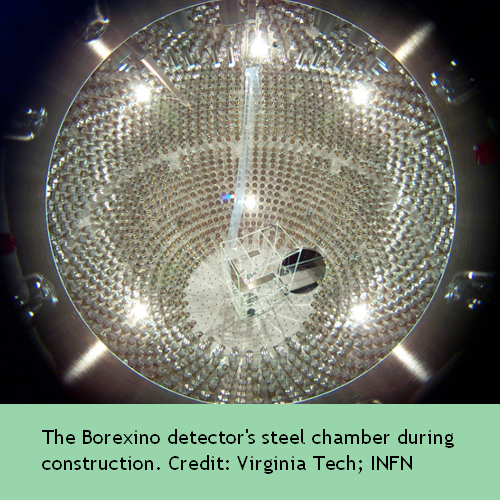               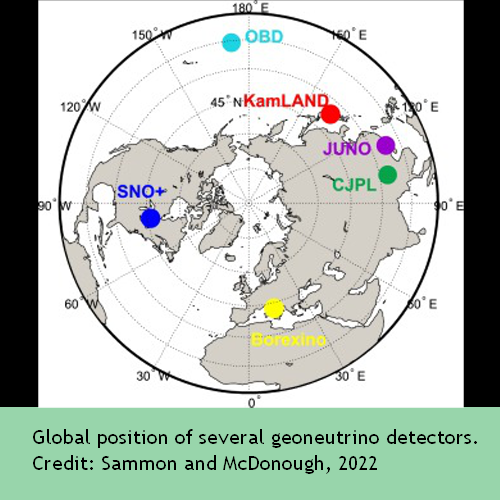

dets = 1; % set the detector

**Do you want to calculate the geoneutrino flux?** If you only want to calculate crustal HPE abundances and *not* perform the flux calculation, uncheck this box:

simple2.calcFlux = true; % set to false to only calculate crustal abundances of HPEs

    if simple2.calcFlux == true
        MASTER.flux.calcFlux = 'true';
    else
        MASTER.flux.calcFlux = 'false'; 
    end
    
%% If you do want to calculate the geoneutrino flux, then we will create a table with antineutrino detector properties, such as location and detector efficiency:

if simple2.calcFlux == true

        % -- Define Possible Detectors --
        % Name, longitude, latitude, depth (m), detector efficiency,
        % protons, Reference Point (bottom left lon/lat coordinates of the near field cell range)
        
        detectors = {137.31, 36.43, 1000, 0.7, 5.98*10^31,[134,34];... %KamLAND - Araki etal. (2005) 
                     13.57, 42.45, 1400, 0.842, 9.76E+30,[10,40];...   %Borexino - Wikipedia LNGS
                     -81.201, 46.475, 2092, 0.8, 5.76E+31,[-84,44];...  %SNO+ - Chen (2007), Andringa etal. (2016)
                     112.518, 22.118, 700, 0.8, 1.29E+33,[109,20];...   %JUNO - An etal. (2016) JUNO Yellowbook
                     101.71, 28.15, 2400, 0.8, 2.16E+32,[99,26];...    %Jinping - Beacom etal. (2016) letter of intent
                     -156.32, 19.72, 0, 0.8, 0,[-160,18];         %Hawaii
                     }; 
        detectors = cell2table(detectors);
        detectors.Properties.RowNames = {'KamLAND','Borexino','SNO','JUNO','Jinping','Hawaii'};
        detectors.Properties.VariableNames = {'Longitude','Latitude','Depth (m)','Efficiency','Protons','Reference Point (lon/lat)'};

    % - Choose Detector -
        det = detectors(dets,:); 
            MASTER.detector = det; 
else
        det = 0;
end 

detectors % this just displays the table we created above

detectors = 6×6 table
                Longitude    Latitude    Depth (m)    Efficiency    Protons     Reference Point (lon/lat)
                _________    ________    _________    __________    ________    _________________________

    KamLAND       137.31       36.43       1000           0.7       5.98e+31           134      34       
    Borexino       13.57       42.45       1400         0.842       9.76e+30            10      40       
    SNO          -81.201      46.475       2092           0.8       5.76e+31           -84      44       
    JUNO          112.52      22.118        700           0.8       1.29e+33           109      20       
    Jinping       101.71       28.15       2400     

*Calculation references: *[*An et al. (2016)*](https://doi.org/10.48550/arXiv.1507.05613)*, *[*Andringa et al. (2016)*](https://onlinelibrary.wiley.com/doi/10.1155/2016/6194250)*, *[*Araki et al. (2005)*](https://www.nature.com/articles/nature03980)*, *[*Beacom et al. (2016)*](https://doi.org/10.48550/arXiv.1602.01733)*, *[*Chen (2007)*](https://doi.org/10.1063/1.2818544)*, *[*Borexino Wiki Page*](https://en.wikipedia.org/wiki/Borexino)

#### Lithospheric Near-Field vs. Far-Field

The total geoneutrino flux signal is the sum of geoneutrinos from the (asthenospheric) mantle, far-field lithosphere, and near-field lithosphere. Far-field and near-field refer to conceptual constructs, splitting the lithosphere into, essentially, "near the detector" and "everywhere else". 

For coding purposes, the near-field can be defined as either 1) a circle with a 500km radius centered on the detector ('Nearest' method), or 2) a rectangle comprised of the closest 6 degrees longitude x 4 degrees latitude ('Traditional' method).

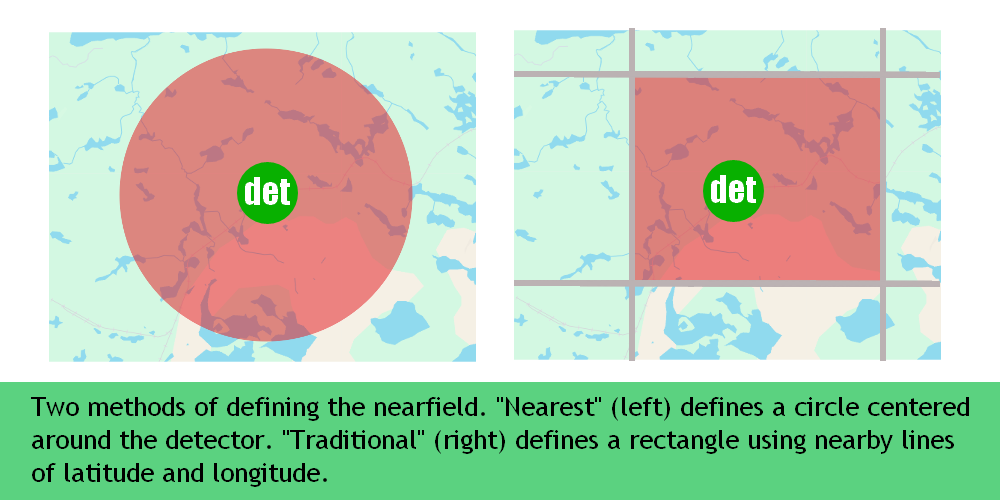

The near-field selection method should, theoretically, not affect the final result of the calculations. However, one method might be preferred over another if there are special regions of interest around the detector or if the user plans to insert their own high resolution model with a specific geometry. 

% -- Near Field Method --
MASTER.flux.nearField = "Traditional";

### B) Choose a Geophysical Model

These seismologically based geophysical models are "crustal profiles" that define the thickness, density and compressional ($V_p$) and shear wave ($V_s$) velocities for seven layers (ice, water, soft sediments, hard sediments, upper, middle, and lower crust). Values for $V_p$ are based on field measurements, whereas empirical $V_p -V_s$ and $V_p$-density relationships are used to establish values for $V_s$ and density. 

- **CRUST2.0** ([Laske et al., 2001](https://igppweb.ucsd.edu/~gabi/crust2);[Bassin et al. 2000](https://www.scirp.org/reference/referencespapers?referenceid=1349393)) describes the crust in 2° x 2° resolution and **CRUST1.0** ([Laske et al., 2013](https://igppweb.ucsd.edu/~gabi/crust1.html)) is a 1° x 1° model. Both are given in geographical coordinate reference space. 

- **LITHO1.0** ([Pasyanos et al., 2014](https://doi.org/10.1002/2013JB010626)) is a 1° x 1° tessellated model that extends beyond crust to the upper mantle and asthenosphere. It also uses surface wave inversions for determining $V_s$ for the crust and lithospheric mantle. 

- **ECM1** ([Mooney et al., 2023](http://mooney%20et%20al.%2C%202023)) is a 1° x 1° model covering the crust and lithospheric mantle and asthenosphere and has more data than the earlier crustal models. It uses S-wave velocity data from field measurements and describes the crust to Moho depths at 5 km intervals for the continents and 2 km intervals for the oceans, incorporating crustal thicknesses from oceanic and continental sediment databases.

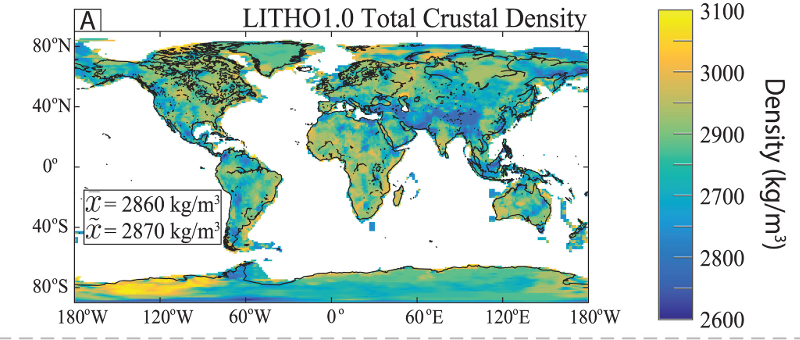      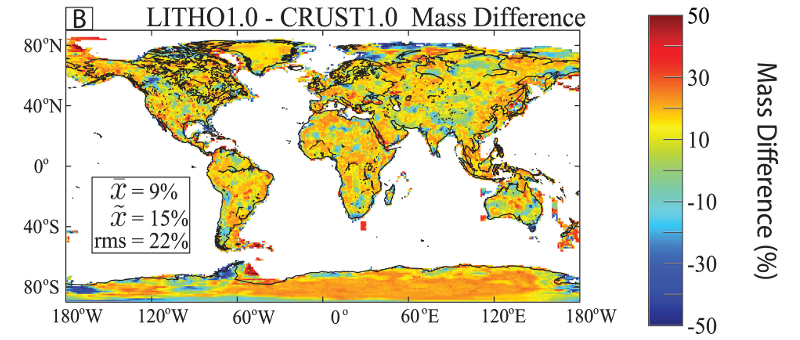

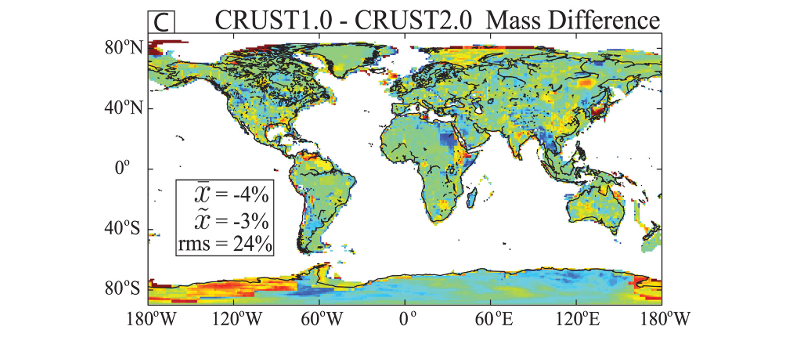      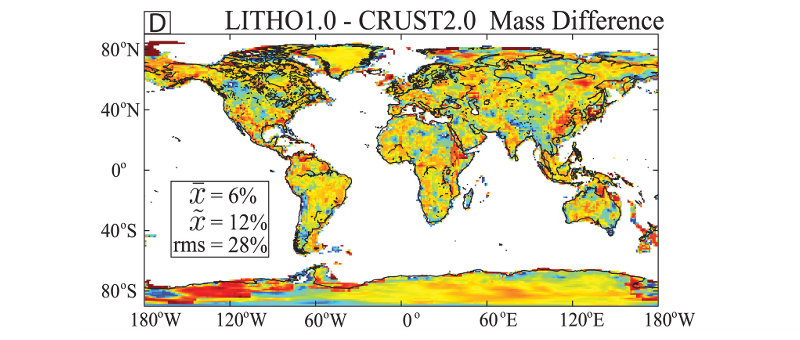

models = 1;

% -- Define Geophysical Model for Lithosphere -- (previous input)
    N = {'Litho1';'Crust1';'Crust2';'ECM1'}; 
    model = N{models}; % 'Crust1','Crust2'
    MASTER.model = model;     

% -- Load Geophysical Model for Lithosphere -- 
    if strcmp(model,'Litho1')
        % -- Load LITHO1.0 Data -- (Pasyanos et al. 2014)
        load('LITHO1_Data.mat')
        GeoPhys = Litho1; % set geophysical model variable
        GeoPhys.name = 'Litho1';
    elseif strcmp(model,'Crust1')
        % -- Load CRUST1.0 Data -- (Laske et al. 2013)
        load('CRUST1_Data.mat')
        GeoPhys = Crust1; % set geophysical model variable
        GeoPhys.name = 'Crust1';
    elseif strcmp(model,'Crust2')
        % -- Load Crust2.0 Data -- (Bassin et al. 2000)
        load('CRUST2_Data.mat')
        GeoPhys = Crust2; % set geophysical model variable
        GeoPhys.name = 'Crust2';
     elseif strcmp(model,'ECM1')
        % -- Load Crust2.0 Data -- (Bassin et al. 2000)
        load('ECM1_Data.mat')
        GeoPhys = ECM1; % set geophysical model variable
        GeoPhys.name = 'ECM1';
    else 
        error('Wrong inputed geophysical model: "%s"',model)
    end   
    
if size(det,2)>1
    d = det.Properties.RowNames{1}; 
else
    d = 'noFlux';
end

#### Logically index continental/oceanic crust

Some of the geophysical models have different number and letter designations for the oceanic and continental crust. Based on the keys provided by model authors, we assign all crustal types a designation of either "continental - 1" or "oceanic - 0". Due to its depletion in HPEs and relatively uniform chemical composition ([White and Klein, 2014](https://www.sciencedirect.com/science/article/abs/pii/B9780080959757003156?via%3Dihub)), oceanic crust is treated as one group in geoneutrino calculations. Whether or not continental crust is treated as one group or split into separate sub-types may be an option in future versions of this program.

*PREM Model reference: *[*Dziewonski and Anderson (1981)*](https://doi.org/10.1016/0031-9201(81)90046-7)


if strcmp(model,'Crust1') 
    
    % Assign a value of 1 if the cell has a crust type that we designate as cc, oc, stable, or Archean crust.  Designation as part of one of these 4 broad 
    % categories is performed by us based on the names given by LITHO1.0 (actually CRUST1.0). All other values are 0. 
   
    % Oceanic Crust: 
    % 26 = A1 normal oceanic
    % 27 = A0 oceans 3 Myrs and younger
    % 28 = B- melt affected o.c. and oceanic plateaus
    % 31 = V1 Inactive Ridge, Alpha ridge
    % 36 = Y3 Caspian Sea Oceanic

    oc_types = [26,27,28,31,36];  %Crust1.0 data types
    oc = any(bsxfun(@eq,oc_types,GeoPhys.type(:,3)),2); clear oc_types
    cc = ~oc; 

elseif strcmp(model,'ECM1')|| strcmp(model,'Litho1')
    disp('Oceanic and continental crust locations already defined in input file')

elseif strcmp(model,'Crust2')
   % ----------  Logically index cc, oc, stable, and Archean crust  --------
    %{ 

    Oceanic Crust = A and B types
    A = normal oceanic 
    B = melt affected o.c. and oceanic plateaus
    %}

    oceanic = {'A0';'A1';'A2';'A3';'A4';'A5';'A6';'A7';'A8';'A9';'AA';'AB';...
        'AC';'BO';'B1';'B2';'B3';'B4';'B5';'B6';'B7';'B8';'B9';'BA';'BB';'BC';'BD'}; 
    idx = zeros(length(GeoPhys.latlon),1);
    for i = 1:length(oceanic)
        x= strcmp(GeoPhys.type,oceanic{i}); 
        idx = idx+x; 
    end
    oc = any(idx,2); %convert to logical
    cc = ~oc; 
end

Oceanic and continental crust locations already defined in input file


% Load Preliminary Reference Earth Model (Dziewonski and Anderson, 1981)    
    load PREM.mat    % PREM model is used to define mantle mass proportions later in the code

% Load Diary file to log any outputs to the command window
    str.diary = sprintf('myDiaryFile_%s_%s_%s.txt',model,d,datetime('now','format','MM_dd_yyyy_HH_mm')); 
    diary(str.diary)

### C) Choose Deep Crust Calculation Method

The [**Huang et al. (2013)**](https://agupubs.onlinelibrary.wiley.com/doi/10.1002/ggge.20129) method averages three geophysical crustal models (CRUST1.0, CRUST2.0, and LITHO1.0) along with uncertainty estimates and gravimetric anomalies (GEMMA) to calculate the HPE abundance yielded from a given average crustal thickness (using Monte Carlo simulations).

The **Bivariate** method populates a variable with the index to a mineralogical crust bin, where the frequency of occurrence for each bin is equal to the probability of each bin from the sample set. The bins are granulite (continental crust) and amphibolite (oceanic crust).

methods = 1;
  % -- Define method for determining MC + LC abundances --
    simple2.meth = methods; %1 = H13 method, 2 = bivariate 
    if simple2.meth == 1
        MASTER.method = 'Huang et al. 2013'; %record method to variable with run information
    elseif simple2.meth == 2
        MASTER.method = 'Bivariate Analysis ';
    end
% Load Bivariate Data (Vp vs SiO2 and SiO2 vs U,Th,K for granulite/amphibolite) 
simple2.bivar = load('BivarData_04042018.mat'); 
MASTER.method = methods;

### D) Define Monte Carlo Iterations

Monte Carlo is a mathematical simulation technique that is used to predict the probability of an outcome for an uncertain event. In this case, the "iterations" help to resolve large uncertainties for several geochemical and geophysical parameters in use for calculations (for example, the abundance of U and crustal thickness).

**NOTE:** A value >10,000 is generally good enough!

MASTER.iter = 15; 
iter = MASTER.iter;

### Optional: Define A Parallel Pool

A [**parallel pool**](https://www.mathworks.com/help/parallel-computing/run-code-on-parallel-pools.html) is a set of MATLAB "workers" on a desktop or computing cluster of connected machines. This feature is typically used in "high performance computing (HPC)" clusters to take full advantage of the processing power available. However, a parallel pool can also be used on a standard desktop if your computer's processor has multiple cores. Type the following line of code into the MATLAB command window to check if your MATLAB client has a pool defined already:

**If your device does not have a pool (i.e. 0x0 array with no properties) or you are running this code with MATLAB Online, DO NOT create a new one! Leave the check box unchecked!** Otherwise, check the box and then specify below the number of cores that you want in your parallel pool. 

runparpool = true; % do you want to set up a parpool?
poolsize = 8

poolsize = 8

    maxNumCompThreads(poolsize);

****If MATLAB cannot run calculations in parallel on your machine (e.g., only one core, licensing issues), then it will override the above input and create a "parallel pool" of just 1 worker. *

**GEONU will generate several files that describe run parameters and variables in order to assist with troubleshooting. **


%% -- Define Model Space --
    
%clearvars -except dets methods models N iter MASTER p poolsize
tstart = tic; 

% - Record Start time -    
    % "MASTER" is a variable to record information about the run
    MASTER.start = datetime("now",'format','yyyy-MM-dd HH:mm:ss.SSS'); 
    MASTER.message = "TestRun01"; % Message describing run

% put runparpoolhere
if runparpool == 1
    p = gcp('nocreate')
    if isempty(p) %check if parallel pool exists. If no, start pool.
        myCluster=parcluster('local'); myCluster.NumWorkers=poolsize; parpool(myCluster,poolsize)
    elseif p.NumWorkers ~= poolsize % if current is different, then restart pool
        delete(gcp('nocreate'))
        myCluster=parcluster('local'); myCluster.NumWorkers=poolsize; parpool(myCluster,poolsize)
    else %otherwise do nothing
        poolsize = p.NumWorkers; 
        gcp %prints parpool information
    end
end


p = 

 ProcessPool with properties: 

            Connected: true
           NumWorkers: 8
                 Busy: false
              Cluster: 


ans = 

 ProcessPool with properties: 

            Connected: true
           NumWorkers: 8
                 Busy: false
              Cluster: 

    
 clear data_load x detectors selection p poolsize % clearing variables that are no longer needed

## ***~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-***

## Step 2: Preallocate Variables

### Beyond this point, user input is only required for Step 3.1 parts B & C.

[Preallocation](https://www.mathworks.com/help/matlab/matlab_prog/preallocating-arrays.html), or predefining the amount of memory needed for variables, increases the speed of MATLAB code. By preallocating many of our large variables here, we are telling MATLAB how much memory to reserve for our results later, thus saving computational time and power.

- We preallocate space for subfields within the different layers of the lithospheric model (e.g., s3, UC, LM). Each subfield within these variable structures will contain different information pertaining to that layer of the lithospheric model. Here we preallocate space for the abundances of U, Th, and K, heat flow (HF); the total mass of these HPEs in each layer; and the flux of geoneutrinos detected from${}^{238}U$and ${}^{232}{\textrm{Th}}$. These fields are simply populated with three columns of 0's for now, one column each for the mean value, and the positive and negative uncertainties, to be filled in later.

% -- Allocate empty subfields to each low resolution layer (to be filled in later) --
    n = {'aU';'aTh';'aK';'hf'};
    x = zeros(length(GeoPhys.latlon),3); % 3 columns for mean, + uncertainty, - unc.


    for i = 1:length(n)
        ice(:).(n{i})   = deal(x);
        water(:).(n{i}) = deal(x);
        UC(:).(n{i})    = deal(x);
        MC(:).(n{i})    = deal(x);
        LC(:).(n{i})    = deal(x);
        LM(:).(n{i})    = deal(x);
        s1(:).(n{i})    = deal(x);
        s2(:).(n{i})    = deal(x);
        s3(:).(n{i})    = deal(x);

    end           
    % - Allocate empty subfields within the 'mass' subfield
    n = {'mass';'U';'Th';'K'};
    for i = 1:length(n)
        ice.mass(:).(n{i})   = deal(x);
        water.mass(:).(n{i}) = deal(x);
        UC.mass(:).(n{i})    = deal(x);
        MC.mass(:).(n{i})    = deal(x);
        LC.mass(:).(n{i})    = deal(x);
        LM.mass(:).(n{i})    = deal(x);
        s1.mass(:).(n{i})    = deal(x);
        s2.mass(:).(n{i})    = deal(x);
        s3.mass(:).(n{i})    = deal(x);
    end           
    
      % - Allocate empty subfields within the 'flux' subfield
    n = {'U238','Th232'};
    for i = 1:length(n)
        ice.flux(:).(n{i})   = deal(x);
        water.flux(:).(n{i}) = deal(x);
        UC.flux(:).(n{i})    = deal(x);
        MC.flux(:).(n{i})    = deal(x);
        LC.flux(:).(n{i})    = deal(x);
        LM.flux(:).(n{i})    = deal(x);
        s1.flux(:).(n{i})    = deal(x);
        s2.flux(:).(n{i})    = deal(x);
        s3.flux(:).(n{i})    = deal(x);
    end     

      clear n x i

- Next, we predefine variables that will be used in "parfor" loop. These variables have values added to them in every iteration and must exist before the loop starts. For each layer of the lithospheric model, the following variables are predefined: 

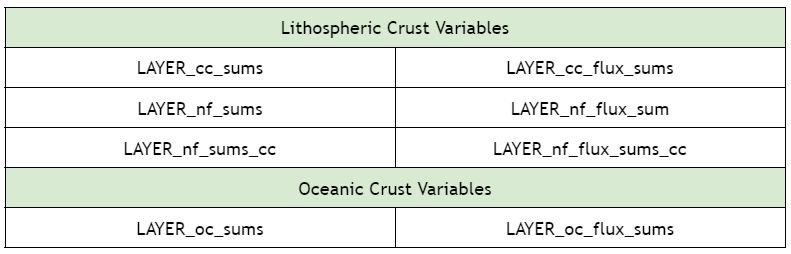

- Nearfield sums for oceanic layers are not gathered explicitly into a separate variable. They can be calculated by subtracting LAYER_nf_sums_cc from LAYER_nf_sums (near-field sums, minus the contribution of near-field sums from the continental crust/lithosphere will leave the contribution from near-field oceanic crust sums as the remainder).

    %- sums variables
    [s1_cc_sums,s2_cc_sums,s3_cc_sums,UC_cc_sums,MC_cc_sums,LC_cc_sums,LM_cc_sums,...
        s1_nf_sums,s2_nf_sums,s3_nf_sums,UC_nf_sums,MC_nf_sums,LC_nf_sums,LM_nf_sums,...
        s1_nf_sums_cc,s2_nf_sums_cc,s3_nf_sums_cc,UC_nf_sums_cc,MC_nf_sums_cc,...
        LC_nf_sums_cc,LM_nf_sums_cc]...
        = deal(zeros(iter,9));  
    
    [s1_oc_sums,s2_oc_sums,s3_oc_sums,UC_oc_sums,MC_oc_sums,LC_oc_sums,LM_oc_sums]...
        = deal(zeros(iter,9));     
    

## ***~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-***

## Step 3.1: Define Parameters for Calculations

### A) Define Middle and Lower Crust Variable Correlations

The method used for defining the correlation between variables in the middle and lower continental crust is selected above in Step One.  This section explains each method in further detail.

        The abundance of U and Th in the lower crust has been modeled in various ways. A popular method is to relate the velocity of compressional waves as they travel through the crust to the major oxide (namely ${\textrm{SiO}}_2$) composition of the crust (please review [Huang et al., 2013](https://agupubs.onlinelibrary.wiley.com/doi/10.1002/ggge.20129) for more information on their methods). The Bivariate Method uses ${\textrm{SiO}}_2$ and HPE abundance data from this paper but treats the distribution of the chemical abundances as non-parametric, meaning it makes no assumptions about the shape of the data distribution. The bivariate method introduces greater uncertainty into the correlation between ${\textrm{SiO}}_2$ and HPEs and is explained further in [Wipperfurth and McDonough (2019)](https://drum.lib.umd.edu/items/caa3a99d-35de-4b3f-8c41-9d60f7005445).

#### HUANG ET AL. 2013 METHOD

**Define random uniform distribution for correlation**

        We will create a variable of random numbers which will define where (what percentile) on a distribution we select a value, e.g., both random numbers will be from the high-end of a distribution rather than random. This has to be done before the for-loop, otherwise each iteration of the for-loop might randomly select numbers similar to the last iteration. Additionally, if done inside the for-loop, a very low U or Th value might be randomly selected to be pair with a very high SiO2 value - a situation for which there is currently no published justification. For instance, mafic granulites do not spontaneously contain high concentrations of U.

        We need different correlations for each lithospheric layer, although within a layer, all of the cells (spatially bound by latitude and longitude) use the same correlation variable. The function "rand_n" is a local function defined at the end of the script.  This function outputs "0" if iter =1, which causes the code to use the central value for the distribution. 

Separate correlations are generated for: 

- `crustal layer thickness`

- `Vp and density (same correlation value)`

- `HPE abundance`


      
n = {'s1';'s2';'s3';'UC';'MC';'LC';'LM'};
x = rand_n(iter); %for thickness correlation, which is same for all layers
    
  for i = 1:length(n)    
    cor(:).(n{i}).vp = rand_n(iter); %"rand_n" is local function, see end of script
    cor(:).(n{i}).abund = rand_n(iter);
    cor(:).(n{i}).thick = x;
  end

    % Abundances endmember (for Huang et al. 2013 method)
cor.MC.end.abund = rand_n(iter); % for felsic and mafic endmembers in MC (Huang et al. method)
cor.LC.end.abund = rand_n(iter); % for felsic and mafic endmembers in LC (Huang et al. method)

cor.MC.bivar.abund = rand_n(iter); % for abundance of U, Th, K for each SiO2 bin
cor.LC.bivar.abund = rand_n(iter); 

    % Vp endmember (for Huang et al. 2013 method)
cor.MC.end.vp = rand_n(iter); % for felsic and mafic endmembers in MC (Huang et al. method)
cor.LC.end.vp = rand_n(iter); % for felsic and mafic endmembers in LC (Huang et al. method)
    
    % Abundance endmember (for BSE and mantle mass balance)
cor.bse = rand_n(iter); 
cor.man = rand_n(iter);

#### BIVARIATE METHOD

**Calculate correlation for bi-variate analysis **

The bivariate analysis (Vp-${\textrm{SiO}}_2$) does not have a set PDF so this needs to be done carefully to take into account the distribution (which isn't Gaussian or log-normal). The following code populates a variable with the index to an SiO2 bin, where the frequency of occurrence for each bin is equal to the probability of each bin from the sample set.

- **Granulite: **Data from granulite facies rocks is used as a lower crust compositional proxy.

    for i = 1:length(simple2.bivar.seis.gran.prob(1,:)) % loop through Vp bins
        P = simple2.bivar.seis.gran.prob(:,i); %probability of each SiO2 bin (row) for each Vp bin (column)

        x = cumsum([0 P(:).'/sum(P(:))]); %cumulative sum of # of samples for givin Vp bin
        x(end) = 1e3*eps + x(end); % sets end value slightly larger than 1 (why?)
        % The following code creates a matrix of length = iter of randomly
        % selected (based on probability from P) SiO2 bins. The syntax
        % "[~,~,X] = histcounts"returns the bin edges (really SiO2 bin) 
        % which we will use later for indexing SiO2 fit parameters. 
        [~,~,cor.LC.bivar.sio2(:,i)] = histcounts(rand(iter,1),x); % provides length = iter of bins to 
    end

- **Amphibolite: **Data from amphibolite facies rocks is used as a middle crust compositional proxy.

    for i = 1:length(simple2.bivar.seis.amp.prob(1,:))
        P = simple2.bivar.seis.amp.prob(:,i); 

        x = cumsum([0 P(:).'/sum(P(:))]);
        x(end) = 1e3*eps + x(end);
        [~,~,cor.MC.bivar.sio2(:,i)] = histcounts(rand(iter,1),x);% sorted so there is correlation, ok since no other correlation is sorted
    end
    clear P x

### B) Define Abundance Information

**K ratio and abundance**

We define and use the abundance of K , as well as the mass fraction of its radioactive isotope, 40K. K abundance in rocks is generally reported as K2O. Therefore, we also calculate the molar mass ratio of K to K2O. 

    K.r = (2*39.0983)/((2*39.0983)+(15.999)); %ratio of K/K20 mass = ~.83
    K.b = 0.00011959;  % mass fraction of K that is K40 (0.000117 is atomic frac)   

#### Assign HPE abundances to oc, UC, LM, and sediments

For the following HPE abundances, the value is listed in the first column, the positive uncertainty in the second column, and the negative uncertainty in the third column. All values are listed in units of kg/kg.

**Oceanic Crust abundances - (default: **[**White and Klein (2014)**](https://www.sciencedirect.com/science/article/abs/pii/B9780080959757003156?via%3Dihub)**, tbl 8; uncertainty = 30% (**[**Huang et al. 2013**](https://agupubs.onlinelibrary.wiley.com/doi/10.1002/ggge.20129)**))**

    oceanic_abund_U = [0.07, 0.021, 0.021]*10^-6;
    oceanic_abund_Th = [0.210, 0.063, 0.063]*10^-6;
    oceanic_abund_K = [0.0716, 0.0215, 0.0215]*10^-2;

    % preallocate space for oceanic crust HPE abundance variables
    oc_aU = zeros(length(oc),3);  
    oc_aTh = zeros(length(oc),3); 
    oc_aK = zeros(length(oc),3); 

    % the 'repmat' function is used to repeat the matrix (in this first
    % case [0.07 0.021 0.021]). Then we logically index into the oceanic
    % crust abundance variables oc_a* and write in that repeated matrix. 
    % Anywhere the logical oc == 0 is where there is continental crust in
    % our model, not oceanic crust. The spaces that are not filled in with
    % oceanic crust abundances will later be filled in with continental
    % crust abundances. LAURA will look into streamlining these few steps
    % in the future.

    x  = repmat(oceanic_abund_U,sum(oc),1); 
    oc_aU(oc,:) = x; %create temp variable oc_a*

    x  = repmat(oceanic_abund_Th,sum(oc),1); 
    oc_aTh(oc,:) = x; 
    
    x  = repmat(oceanic_abund_K,sum(oc),1); 
    oc_aK(oc,:) = x;
    
    
    % - Assign OC stats to UC, MC, and LC -
    [UC.aU,  MC.aU,  LC.aU]  = deal(oc_aU);  %(kg/kg)
    [UC.aTh, MC.aTh, LC.aTh] = deal(oc_aTh); %(kg/kg)
    [UC.aK,  MC.aK,  LC.aK]  = deal(oc_aK);  %(kg/kg K (not K40))

    clear oc_aU oc_aTh oc_aK

**UC (upper crust) abundances -- (default: **[**Rudnick and Gao (2014**](https://doi.org/10.1016/B978-0-08-095975-7.00301-6)**), tbl 3)**

    UC_abund_U = [2.7 0.6 0.6]*10^-6;
    UC_abund_Th = [10.5 1.0 1.0]*10^-6;
    UC_abund_K = [2.32 0.19 0.19]*10^-2;

    
    UC.aU(cc,:)  = repmat(UC_abund_U,sum(cc),1);    %(kg/kg)
    UC.aTh(cc,:) = repmat(UC_abund_Th,sum(cc),1);   %(kg/kg)
    UC.aK(cc,:)  = repmat(UC_abund_K,sum(cc),1); %(kg/kg K, not K40)

**LM (continental lithospheric mantle) peridotite abundance -- (default: **[**Huang et al. 2013**](https://agupubs.onlinelibrary.wiley.com/doi/10.1002/ggge.20129)**, tbl 5)**

    LM_abund_U = [0.033, 0.049, 0.020]*10^-6;
    LM_abund_Th = [0.150, 0.277, 0.097]*10^-6;
    LM_abund_K = [0.0315, 0.04316, 0.01826]*10^-2;
    
    LM.aU(cc,:)  = repmat(LM_abund_U,sum(cc),1); %(kg/kg)
    LM.aTh(cc,:) = repmat(LM_abund_Th,sum(cc),1); %(kg/kg)
    LM.aK(cc,:)  = repmat(LM_abund_K,sum(cc),1); %(kg/kg K, not K40)

**Sediment abundances -- (default: **[**Plank, 2014**](https://doi.org/10.1016/B978-0-08-095975-7.00319-3)** GLOSS II model, tbl 2)**

Same abundance values used for sediment layers s1, s2, and s3. *Be aware that GLOSS II reports K abundance as K2O and therefore must be converted to K by multiplying by the molar mass ratio (K.r) defined in the first line of code in this section.*

    sed_abund_U = [1.73, 0.09, 0.09].*10^-6;
    sed_abund_Th = [8.10, 0.59, 0.59].*10^-6;
    sed_abund_K = [2.21, 0.14, 0.14].*10^-2.*K.r;
    
    sed.U  = repmat(sed_abund_U,length(UC.lat),1); % temp variable
    sed.Th = repmat(sed_abund_Th,length(UC.lat),1); 
    sed.K  = repmat(sed_abund_K,length(UC.lat),1); 
    
    [s1.aU,  s2.aU,  s3.aU]    = deal(sed.U);  %(kg/kg)
    [s1.aTh, s2.aTh, s3.aTh]   = deal(sed.Th); %(kg/kg)
    [s1.aK,  s2.aK,  s3.aK]    = deal(sed.K);  %(kg/kg K, not K40)
    clear sed

**Middle Crust and Lower Crust**

**Define Granulite and Amphibolite abundance endmembers**

The Th and U abundances for the middle and lower continental crust will be calculated based on the [Huang et al. (2013](https://agupubs.onlinelibrary.wiley.com/doi/10.1002/ggge.20129)) method with correlations dependent on the correlation method selected above: Huang et al. or Bivariate Method. The HPE content in felsic (f) and mafic (m) endmembers of middle and lower crustal rocks are defined. Recall that HPEs are correlated to ${\textrm{SiO}}_2$ which is in turn correlated to Vp. Vp for a location in the middle or lower crust is given by your selected lithospheric model (e.g., CRUST1.0).

    ppm = 10^-6; 
    wt = 10^-2 * 0.000112 * 0.83; %10^-2 to bring to kg/kg, .000112 to bring K to K40, and 0.83 for K20 to K 
      
    % - Middle crust (amphibolite) (log normal distribution)
    am.f.U  = logdist(1.37,1.03,0.59,iter,cor.MC.end.abund)*ppm;    am.m.U  = logdist(0.37,0.39,0.19,iter,cor.MC.end.abund)*ppm; %U
    am.f.Th = logdist(8.27,8.12,4.10,iter,cor.MC.end.abund)*ppm;    am.m.Th = logdist(0.58,0.57,0.29,iter,cor.MC.end.abund)*ppm; %Th
    am.f.K  = logdist(2.89,1.81,1.11,iter,cor.MC.end.abund)*wt;     am.m.K  = logdist(0.50,0.41,0.23,iter,cor.MC.end.abund)*wt; %K
    
    % - Lower crust (granulite)
    gr.f.U  = logdist(0.42,0.41,0.21,iter,cor.LC.end.abund)*ppm;    gr.m.U  = logdist(0.10,0.14,0.06,iter,cor.LC.end.abund)*ppm;
    gr.f.Th = logdist(3.87,7.35,2.54,iter,cor.LC.end.abund)*ppm;    gr.m.Th = logdist(0.30,0.46,0.18,iter,cor.LC.end.abund)*ppm;
    gr.f.K  = logdist(2.71,2.05,1.17,iter,cor.LC.end.abund)*wt;     gr.m.K  = logdist(0.39,0.31,0.17,iter,cor.LC.end.abund)*wt;    
    
    simple2.am = am; 
    simple2.gr = gr; 

**Define Amphibolite and Granulite Vp endmembers**

The compressional velocities (Vp) for the felsic (f) and mafic (m) endmember compositions are set to 6.34 $\pm$ 0.16 km/s and 6.98 $\pm$ 0.20 km/s for amphibolite, respectively. The Vp's for granulite endmembers are 6.52 $\pm$ 0.19 km/s (f) and 7.21 $\pm$ 0.20 km/s (m).

  % - Middle crust (amphibolite)
    Vp.MC.f = randist(6.34,0.16,iter,cor.MC.end.vp); %(km/s) (normal dist.)
    Vp.MC.m = randist(6.98,0.20,iter,cor.MC.end.vp); %(km/s) (normal dist.)

    %- Lower crust (granulite)
    Vp.LC.f = randist(6.52,0.19,iter,cor.LC.end.vp);  %(km/s) (normal dist.)
    Vp.LC.m = randist(7.21,0.20,iter,cor.LC.end.vp);  %(km/s) (normal dist.)



### **C) Mantle Geoneutrino Signal and Style **

If you want to calculate the mantle geoneutrino flux here, you will have to make assumptions about the total HPE content in Earth. The purpose of geoneutrino flux measurement experiments is to *observe* the HPE content of the mantle so that we do not have to assume HPE content in Earth. HOWEVER, it is sometimes useful to calculate what the mantle geoneutrino flux *would be *if testing a theoretical HPE model, predicting what the flux would be at an as-of-yet not built geoneutrino detector, or for simulating different geometries of enriched layers in the mantle. If we want to test any of these options, we need to fill out the following lines of code with bulk silicate Earth's (BSE's) Th/U mass ratio, K/U mass ratio, and total U concentration.

So, **do you want to calculate a mantle geoneutrino signal**? If yes, do you want a **layered mantle **or** homogeneous mantle**?

% -- Calculate mantle signal? --
    calcMantle = false; 

% -- Decide Mantle structure --
    if calcMantle == true
        % Two Options for mantle: Homogenous (no enriched or depleted
        % mantle) or Layered (enriched mantle = 19% of mantle)
        calcMantleLayered = true; % layered or homogeneous mantle
        MASTER.mantle.calc = 'true';

        if calcMantleLayered == true
            MASTER.mantle.Style = 'Layered';
        else
            MASTER.mantle.Style = 'Homogenous';
        end
    %end
    
    simple2.calcMantleLayered = calcMantleLayered; 
    else
    MASTER.mantle.calc = 'false';
    simple2.calcMantleLayered = 'true';
    end

**Mantle HPE Abundance Information - U in ppb**

mantle_U_total = 19; % plus 20% uncertainty associated with mantle U total

**Then, we set mass balance values for U, Th, and K in mantle -- (references: **[**McDonough and Sun (1995)**](https://www.sciencedirect.com/science/article/abs/pii/0009254194001404)**, **[**Arevalo et al. (2013**](https://agupubs.onlinelibrary.wiley.com/doi/10.1002/ggge.20152)**) and Th/U from **[**Wipperfurth et al. (2018**](https://www.sciencedirect.com/science/article/abs/pii/S0012821X18303807?via%3Dihub)**))**

    ThUratio = logdist(3.776,0.122,0.075,iter,cor.bse);  %mass ratio Wipperfurth et al. 2018
    KUratio = randist(13800,1300,iter,cor.bse); % value from Arevalo et al. 2009 
    %bse.aU = 6*10^-9 + 40*10^-9*rand(iter,1); % use to test flux from various BSE models
    bse.aU = randist(mantle_U_total,mantle_U_total*0.2,iter,cor.bse)*10^-9; %McDonough and Sun '95  
    bse.aTh = bse.aU.*ThUratio; 
    bse.aK40 = bse.aU.*KUratio*K.b; 

## ***~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-***

## Step 3.2: Define Constants

In this section, several isotope values, probability constants, energy bins, etc., are defined as variables in the code.

### A) Isotope information (hp, mass, molar ratio)

#### Define heat Production from kg of isotope ([McDonough et al., 2020](https://agupubs.onlinelibrary.wiley.com/doi/10.1029/2019GC008865))

    simple2.hp.U238 = 94.936*10^-6;  %(Watt/kg)
    simple2.hp.U235 = 561.65*10^-6; %(Watt/kg)
    simple2.hp.U    = 98.293*10^-6;  %(Watt/kg)
    simple2.hp.Th   = 26.180*10^-6;  %(Watt/kg)
    simple2.hp.K40  = 29.029*10^-6;  %(Watt/kg) K40, not K

#### Define isotope parameters

Molar ratios from [Chart of Nuclides](https://www.nndc.bnl.gov/) (National Nuclear Data Center). Isotope masses from [Table of Nuclides](https://atom.kaeri.re.kr/nuchart/) (Nuclear Data Center at KAERI). Avogadro's Number from [NIST](https://physics.nist.gov/cgi-bin/cuu/Value?na).

    % - Molar Ratio - 
    simple2.iso.molar.U238  = 0.992740; 
    simple2.iso.molar.U235  = 1 - simple2.iso.molar.U238;
    simple2.iso.molar.Th232 = 1.00; 
    simple2.iso.molar.K40   = 0.0001167; % mass ratio = 0.000112

    % - Isotope Mass - (amu)
    simple2.iso.amu.U238  = 238.0507826; 
    simple2.iso.amu.U235  = 235.0439231;
    simple2.iso.amu.Th232 = 232.0380504; 
    simple2.iso.amu.K40   = 39.9639987; 
    simple2.iso.amu.amuKg = 1.660539040*10^-27;

    % - Avogadro's Number - (atom/mole)
    simple2.iso.avgd = 6.022140857*10^23; % http://physics.nist.gov/cgi-bin/cuu/Value?na    

    % - Decay constant - %(/s)
    simple2.iso.dc.U238  = log(2)/(4.4683e9*3.15569e7);  %(/s)
    simple2.iso.dc.U235  = log(2)/(0.70348e9*3.15569e7); %(/s) 
    simple2.iso.dc.Th232 = log(2)/(14.1e9*3.15569e7);   %(/s)
    simple2.iso.dc.K40   = log(2)/(1.262e9*3.15569e7);   %(/s)

### B) Antineutrino parameters 

#### **Oscillation, spectrum, cross-section**

Define geoneutrino oscillation parameters: Values from [Tanabashi et al. 2018](https://journals.aps.org/prd/abstract/10.1103/PhysRevD.98.030001) (Review of Particle Physics), [Patrignani 2016](https://iopscience.iop.org/article/10.1088/1674-1137/40/10/100001/meta) (Chinese Physics C), [Navas et al. 2024](https://pdg.lbl.gov/) (Particle Data Group), and[ Capozzi et al. 2017](https://www.nature.com/articles/ncomms15757). There is no correlation among parameters (or at least it is not known).

    x = (asind(sqrt(0.0240)) - asind(sqrt(0.0215)))/3; % uncertainty (symmetrical)
    the13               = randist(asind(sqrt(0.0215)),x,1);        %(degree) theta 13 center, +, -
    x = (asind(sqrt(0.354)) - asind(sqrt(0.297)))/3; %positive uncertainty (1 sigma)
    y = (asind(sqrt(0.297)) - asind(sqrt(0.250)))/3; % negative uncertainty
    the12               = logdist(asind(sqrt(0.297)),x,y,1);        %(degree) theta 12 
    simple2.pee.delm21  = logdist(7.37,0.59,0.44,1)*10^-5;  %(eV^2) delta-mass 21 
    simple2.pee.delm32n = logdist(2.56,0.13,0.11,1)*10^-3;  %(eV^2) delta-mass 32 normal hierarchy 
    simple2.pee.delm32i = logdist(-2.54,0.12,0.12,1)*10^-3;  %(eV^2) delta-mass 32 inverted hierarchy 
    weak                = asind(sqrt(0.23122));                     %(degree) weak mixing angle from Canas et al. 2016 Physics Letter B

#### **Calculate Oscillation probability constants**

These survival probabilities do not involve distance or energy, so we calculate them now, independent of the Monte Carlo loop.

    simple2.pee.p1 = cosd(the13(1)).^4 .* sind(2.*the12(1)).^2;
    simple2.pee.p2 = sind(2*the13(1)).^2 .* cosd(2.*the12(1)).^2;
    simple2.pee.p3 = sind(2*the13(1)).^2;        

#### **Load and bin geoneutrino spectrum - (**[**Enomoto et al. 2007**](https://www.sciencedirect.com/science/article/abs/pii/S0012821X07001872)**)**

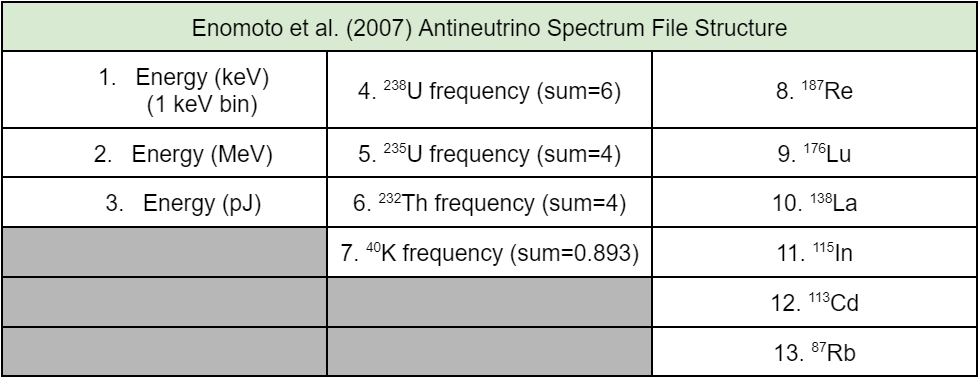

- Then, we define energies at which we will calculate flux. This has to be here so we can pre-define variables.

    E_int =75; %(keV) Energy bin size
    %simple2.energy(:,1) = 1806+E_int/2:E_int:3276-E_int/2; %(keV) 3272 = max but this is easier

    simple2.energy = 0+(E_int/2):E_int:3300; 
    simple2.energy = simple2.energy'; 
    %simple2.energy(:,1) = 0+E_int/2:E_int:3276-E_int/2; %(keV) 3272 = max but this is easier

    MASTER.energy.bin = simple2.energy; 
    MASTER.energy.binsize = E_int;


- [Enomoto et al. 2007](https://www.sciencedirect.com/science/article/abs/pii/S0012821X07001872) antineutrino spectrum is then loaded. The original spectrum was binned at 1 keV, so now it must be re-binned into `E_int` sized energy bins as defined in line 412 of this code.

load 'Enomoto2007_AntineutrinoSpectrum.mat'  

        for i = 1:length(simple2.energy)
            top = round(simple2.energy(i)+0.5*E_int);   % top index
            bot = round(simple2.energy(i)-0.5*E_int+1); % bottom index

            simple2.eno.U238(i,1)  = sum(enomoto(bot:top,4));  
            simple2.eno.U235(i,1)  = sum(enomoto(bot:top,5));
            simple2.eno.Th232(i,1) = sum(enomoto(bot:top,6));  
            simple2.eno.K40(i,1)   = sum(enomoto(bot:top,7));  
        end

- Calculate the number of neutrinos per decay chain (for [Sramek et al., 2016](https://www.nature.com/articles/srep33034), flux equation), and then the antineutrino interaction cross-section (see [Dye 2012](https://agupubs.onlinelibrary.wiley.com/doi/full/10.1029/2012RG000400), eqn 15).

% Neutrinos per decay chain
        simple2.eno.num.U238  = sum(enomoto(:,4)); 
        simple2.eno.num.U235  = sum(enomoto(:,5)); 
        simple2.eno.num.Th232 = sum(enomoto(:,6)); 
        simple2.eno.num.K40   = sum(enomoto(:,7)); 

% Calculate antineutrino interaction cross-section
        me = 0.5109989461; %mass electron (MeV)
    delta = 939.5654133 - 938.2720813; %Mass_Neutron - Mass_Proton (MeV)

% Calculate Cross Section (see Dye 2012 equation 11)(note: me^2 replaces 'me' Dye 2012 equation)
    sigma = zeros(1,length(simple2.energy)); 
    e = simple2.energy/1000; 
    idx = e>1.806;
    sigma(idx) = 9.52*((e(idx)-delta).^2).*sqrt(1-(me^2./(e(idx)-delta).^2))*(10^-44); %cm2

% Define Bin-edges for "Flux vs Distance (m)" plot
        simple2.centers = logspace(2,7.1,100);

        [s1_distCount_sums,s2_distCount_sums,s3_distCount_sums,UC_distCount_sums,...
            MC_distCount_sums,LC_distCount_sums,LM_distCount_sums,man_distCount_sums]...
            = deal(zeros(length(logspace(2,7,100)),length(simple2.energy(:,1))*2));  

- Just as we preallocated memory above for variables that will eventually contain information about the mass and distribution of *HPEs* in different layers of the lithosphere, here we are preallocating variables for the *flux* totals for different layers in the lithosphere.

 [s1_cc_flux_sums,s2_cc_flux_sums,s3_cc_flux_sums,UC_cc_flux_sums,...
        MC_cc_flux_sums,LC_cc_flux_sums,LM_cc_flux_sums,s1_nf_flux_sums,...
        s2_nf_flux_sums,s3_nf_flux_sums,UC_nf_flux_sums,MC_nf_flux_sums,...
        LC_nf_flux_sums,LM_nf_flux_sums,s1_nf_flux_sums_cc,s2_nf_flux_sums_cc,...
        s3_nf_flux_sums_cc,UC_nf_flux_sums_cc,MC_nf_flux_sums_cc,...
        LC_nf_flux_sums_cc,LM_nf_flux_sums_cc]...
        = deal(zeros(iter,length(simple2.energy(:,1))*2));  


    [s1_oc_flux_sums,s2_oc_flux_sums,s3_oc_flux_sums,UC_oc_flux_sums,...
        MC_oc_flux_sums,LC_oc_flux_sums,LM_oc_flux_sums]...
        = deal(zeros(iter,length(simple2.energy(:,1))*2));   


clear prot Tmax x E enomoto top bot E_int % clear variables that are no longer needed to save memory space

## ***~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-***

## Step 4: Perform Non-loop Calculations

These are the final prep calculations done before the Monte Carlo loop. The lines of code in this section find the near-field tiles based on the method chosen above, "Traditional" or "Nearest", and note the latitudes and longitudes bounding these tiles. Then, a unit conversion from SI units to TNU is prepared and descriptive text about the model's runtime parameters is printed to the command window (useful summary when retrieving jobs from a remote cluster and for reminding yourself about your model parameters in the future).

- We must find the radius of Earth at the detector's location, in meters.

if strcmp(MASTER.flux.calcFlux,'true') 

    x = knnsearch([GeoPhys.latlon(:,1),GeoPhys.latlon(:,2)],[det{1,1},det{1,2}]);
    det{1,3} = GeoPhys.r(x) - det{1,3}; clear x 
    det.Properties.VariableNames = {'Longitude','Latitude','Radius','Efficiency','Proton','NearField'};

end

- Then we identify calculation "tiles" as near-field or far-field.

if MASTER.flux.nearField == "Traditional"
    
    % -- Near Field = 4x6 degrees (rectangle; traditional way)
        z = det{1,6}; 
        x = z(1)+0.5:1:z(1)+6-0.5; % longitude centers 
        y = z(2)+0.5:1:z(2)+4-0.5; % latitude centers
        [X,Y] = meshgrid(x,y);
        temp = horzcat(X(:),Y(:));
        

        nearField.idx = knnsearch(GeoPhys.latlon,temp); %indices of nearField cells
        nearField.logic = ismember(GeoPhys.latlon,GeoPhys.latlon(nearField.idx,:),'rows'); %logical index

    else

    % -- Near Field = closest 24 cells (not rectangle)
        
        % Find closest 24 cells
        distance = dis(GeoPhys.latlon(:,1),GeoPhys.latlon(:,2),det{1,1:3},GeoPhys.r,0); 
        x = sort(distance); 
        nearField.idx = knnsearch(distance,x(1:(4*6))); %indeces of nearField cells
        nearField.logic = ismember(GeoPhys.latlon,GeoPhys.latlon(nearField.idx,:),'rows'); %logical index

end

### Calculate Geo-flux parameters to be able to convert measured flux at a given detector to TNU

The output "flux" from the function 'Huang13_Cluster' or 'mantleGeo' outputs in units of kg/m², but the final units we need are neutrino/cm²/s. We remove kg by dividing by the mass of a${}^{238}U$ atom in kg (convert atomic-mass-unit to kg). We convert m² to cm² by dividing by ${10}^4$.  We are now at 1/cm². We multiply by the number of neutrinos emitted per energy per decay chain (neutrino/decay). Finally, we multiply by the decay constant (decay/s) to get neutrino/cm²/s.

iso = simple2.iso; 
eno = simple2.eno;


TNU.U238 = 1/10^4/iso.amu.amuKg / iso.amu.U238 * iso.dc.U238 * eno.U238' .* (10^32) * (3.154*10^7) * 1.0 .* sigma; 

TNU.Th232 = 1/10^4/iso.amu.amuKg / iso.amu.Th232 * iso.dc.Th232 * eno.Th232' .* (10^32) * (3.154*10^7) * 1.0 .* sigma; 

simple2.moho = GeoPhys.moho; 
simple2.model = MASTER.model; 
clear iso eno temp distance z x y X Y

### Output model run information into Command Window

Put this here so it is before time intensive loop. Therefore, if run fails the Model parameters will be identifiable in the Command Window output. Otherwise if it fails it is unclear which run it is.

disp('------------------- Run information ------------------')

------------------- Run information ------------------


fprintf('Start date and time:       %s \n',MASTER.start);

Start date and time:       2024-08-25 13:56:31.491 


fprintf('Geophysical Model:         %s \n',MASTER.model);

Geophysical Model:         Litho1 


fprintf('Number of iterations:      %d \n',MASTER.iter);

Number of iterations:      15 


fprintf('MC + LC Method:            %s \n',MASTER.method);

MC + LC Method:            □ 


fprintf('Calculate Mantle:          %s \n',MASTER.mantle.calc);

Calculate Mantle:          false 


    if strcmp(MASTER.mantle.calc,'true')
    fprintf('Mantle structure:          %s \n',MASTER.mantle.Style); 
    end
fprintf('Calculate Flux:            %s \n',MASTER.flux.calcFlux);

Calculate Flux:            true 


    if strcmp(MASTER.flux.calcFlux,'true')
fprintf('Detector (lon lat):        %s (%0.2f %0.2f) \n',det.Properties.RowNames{1},det.Longitude,det.Latitude)
fprintf('Energy bin size (MeV):     %d \n',MASTER.energy.binsize); 
fprintf('Near-Field style:          %s \n',MASTER.flux.nearField);
    end

Detector (lon lat):        KamLAND (137.31 36.43) 


Energy bin size (MeV):     75 


Near-Field style:          Traditional 


## ***~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-***

## Step 5: The Flux Calculation

### A) Lithosphere Monte Carlo Loop

The Monte Carlo is used to calculate the mass distribution and heat production for each layer. For the middle and lower crust, the abundance of U, Th, and K is calculated from comparison of seismic velocity and petrologic constraints, then the heat production is calculated. Calls to custom functions in this section include: 

rng shuffle %reseed random number generator based on time (DO NOT PUT INTO LOOP, time intensive and maybe logically not correct)
nf_temp = nearField.logic; % Needed, otherwise "nearField" becomes broadcast variable
tic

warning('off','MATLAB:mir_warning_maybe_uninitialized_temporary')

parfor k = 1:length(GeoPhys.latlon) % n = a specific cell (out of 64,800)

temp_P = zeros(iter,1); %temporary pressure, reset every new cell (otherwise it will continue summing between cells
    if cc(k) == 1 

        % -- Input data into "Huang13" function --

         % -  Upper Sediment  (s1; layer 3)    
               [s1_out(k), s1_output_sums,s1_geoResponse(k,:),s1_flux(k),s1_flux_sums,P,s1_distCount]...
                   = Abund_And_Flux(k,iter,'s1',s1,simple2,cor.s1,GeoPhys.r(k),det,temp_P);
              s1_cc_sums = s1_cc_sums + s1_output_sums;
              s1_cc_flux_sums = s1_cc_flux_sums + s1_flux_sums;
              temp_P = temp_P + P; % add up pressure
              
           
         % -  Middle Sediment  (s2; layer 4)    
               [s2_out(k), s2_output_sums,s2_geoResponse(k,:),s2_flux(k),s2_flux_sums,P,s2_distCount]...
                   = Abund_And_Flux(k,iter,'s2',s2,simple2,cor.s2,GeoPhys.r(k),det,temp_P);
              s2_cc_sums = s2_cc_sums + s2_output_sums;  
              s2_cc_flux_sums = s2_cc_flux_sums + s2_flux_sums;
              temp_P = temp_P + P; % add up pressure

         % -  Lower Sediment  (s3; layer 5)    
               [s3_out(k), s3_output_sums,s3_geoResponse(k,:),s3_flux(k),s3_flux_sums,P,s3_distCount]...
                   = Abund_And_Flux(k,iter,'s3',s3,simple2,cor.s3,GeoPhys.r(k),det,temp_P);
              s3_cc_sums = s3_cc_sums + s3_output_sums;               
              s3_cc_flux_sums = s3_cc_flux_sums + s3_flux_sums;
              temp_P = temp_P + P; % add up pressure

         % - Upper Crust (UC; layer 6)      
               [UC_out(k), UC_output_sums,UC_geoResponse(k,:),UC_flux(k),UC_flux_sums,P,UC_distCount]...
                   = Abund_And_Flux(k,iter,'UC',UC,simple2,cor.UC,GeoPhys.r(k),det,temp_P);
              UC_cc_sums = UC_cc_sums + UC_output_sums; 
              UC_cc_flux_sums = UC_cc_flux_sums + UC_flux_sums;
              temp_P = temp_P + P; % add up pressure

         % - Middle Crust (MC; layer 7)      
               [MC_out(k), MC_output_sums,MC_geoResponse(k,:),MC_flux(k),MC_flux_sums,P,MC_distCount]...
                   = Abund_And_Flux(k,iter,'MC',MC,simple2,cor.MC,GeoPhys.r(k),det,temp_P);
              MC_cc_sums = MC_cc_sums + MC_output_sums; 
              MC_cc_flux_sums = MC_cc_flux_sums + MC_flux_sums;
              temp_P = temp_P + P; % add up pressure

         % - Lower Crust (LC; layer 8)      
               [LC_out(k), LC_output_sums,LC_geoResponse(k,:),LC_flux(k),LC_flux_sums,P,LC_distCount]...
                   = Abund_And_Flux(k,iter,'LC',LC,simple2,cor.LC,GeoPhys.r(k),det,temp_P);
              LC_cc_sums = LC_cc_sums + LC_output_sums;   
              LC_cc_flux_sums = LC_cc_flux_sums + LC_flux_sums;
              temp_P = temp_P + P; %moho(n).pressure = stat(P); % Pressure at base of LC (i.e. moho)

         % - Lithospheric Mantle (LM; layer 9)      
               [LM_out(k), LM_output_sums,LM_geoResponse(k,:),LM_flux(k),LM_flux_sums,P,LM_distCount]...
                   = Abund_And_Flux(k,iter,'LM',LM,simple2,cor.LM,GeoPhys.r(k),det,temp_P);
               LM_cc_sums = LM_cc_sums + LM_output_sums;  
               LM_cc_flux_sums = LM_cc_flux_sums + LM_flux_sums; 
               %LAB(n).pressure = stat(temp_P + P); % pressure at base of lithosphere (i.e. LAB)

         
    elseif cc(k) == 0% ----  CALCULATE ATTRIBUTES FOR OCEANIC CRUST --------
            %fprintf('   oc %d \n',n)
                  % -  Upper Sediment  (s1; layer 3)    
                [s1_out(k), s1_output_sums,s1_geoResponse(k,:),s1_flux(k),s1_flux_sums,P,s1_distCount]...
                    = Abund_And_Flux(k,iter,'s1',s1,simple2,cor.s1,GeoPhys.r(k),det,temp_P);
                s1_oc_sums = s1_oc_sums + s1_output_sums;
                s1_oc_flux_sums = s1_oc_flux_sums + s1_flux_sums; 
                temp_P = temp_P + P; % add up pressure

         % -  Middle Sediment  (s2; layer 4)    
               [s2_out(k), s2_output_sums,s2_geoResponse(k,:),s2_flux(k),s2_flux_sums,P,s2_distCount]...
                   = Abund_And_Flux(k,iter,'s2',s2,simple2,cor.s2,GeoPhys.r(k),det,temp_P);
               s2_oc_sums = s2_oc_sums + s2_output_sums;               
               s2_oc_flux_sums = s2_oc_flux_sums + s2_flux_sums;    
               temp_P = temp_P + P; % add up pressure

         % -  Lower Sediment  (s3; layer 5)    
               [s3_out(k), s3_output_sums,s3_geoResponse(k,:),s3_flux(k),s3_flux_sums,P,s3_distCount]...
                   = Abund_And_Flux(k,iter,'s3',s3,simple2,cor.s3,GeoPhys.r(k),det,temp_P);
               s3_oc_sums = s3_oc_sums + s3_output_sums;  
               s3_oc_flux_sums = s3_oc_flux_sums + s3_flux_sums; 
               temp_P = temp_P + P; % add up pressure

         % - Upper Crust (UC; layer 6)      
               [UC_out(k), UC_output_sums,UC_geoResponse(k,:),UC_flux(k),UC_flux_sums,P,UC_distCount]...
                   = Abund_And_Flux(k,iter,'UC',UC,simple2,cor.UC,GeoPhys.r(k),det,temp_P);
              UC_oc_sums = UC_oc_sums + UC_output_sums; 
              UC_oc_flux_sums = UC_oc_flux_sums + UC_flux_sums; 
               temp_P = temp_P + P; % add up pressure   

         % - Middle Crust (MC; layer 7)  (put layer "MC_oc" so it doesnt do
            % abundance calculation) "MC_oc_output_stat" is different size than "MC_output_stat"
               [MC_out(k), MC_output_sums,MC_geoResponse(k,:),MC_flux(k),MC_flux_sums,P,MC_distCount]...
                   = Abund_And_Flux(k,iter,'MC_oc',MC,simple2,cor.MC,GeoPhys.r(k),det,temp_P);
               MC_oc_sums = MC_oc_sums + MC_output_sums; 
               MC_oc_flux_sums = MC_oc_flux_sums + MC_flux_sums; 
               temp_P = temp_P + P; % add up pressure             

         % - Lower Crust (LC; layer 8)      (put layer "LC_oc" so it doesnt do
            % abundance calculation)"LC_oc_output_stat" is different size than "LC_output_stat"
               [LC_out(k), LC_output_sums,LC_geoResponse(k,:),LC_flux(k),LC_flux_sums,P,LC_distCount]...
                   = Abund_And_Flux(k,iter,'LC_oc',LC,simple2,cor.LC,GeoPhys.r(k),det,temp_P);
               LC_oc_sums = LC_oc_sums + LC_output_sums; 
               LC_oc_flux_sums = LC_oc_flux_sums + LC_flux_sums;
               temp_P = temp_P + P; 
               %moho(n).pressure = temp_P + P; % Pressure at base of LC (i.e. moho)

        % - Lithospheric Mantle (LM; layer 9) (need layer = 'LM_oc' so it
        %            fills it in blank
               [LM_out(k), LM_output_sums,LM_geoResponse(k,:),LM_flux(k),LM_flux_sums,P,LM_distCount]...
                   = Abund_And_Flux(k,iter,'LM_oc',LM,simple2,cor.LM,GeoPhys.r(k),det,temp_P);
               LM_oc_sums = LM_oc_sums + LM_output_sums; 
               LM_oc_flux_sums = LM_oc_flux_sums + LM_flux_sums;  
               %LAB(n).pressure = moho(n).pressure + P; % pressure at base of lithosphere (i.e. LAB)

    else
        disp('something is wrong with your logical, so consider this an error message')
    end % end of if else statement
  % -- Record Flux vs Distance information --
            s1_distCount_sums = s1_distCount_sums + s1_distCount; 
            s2_distCount_sums = s2_distCount_sums + s2_distCount; 
            s3_distCount_sums = s3_distCount_sums + s3_distCount; 
            UC_distCount_sums = UC_distCount_sums + UC_distCount;
            MC_distCount_sums = MC_distCount_sums + MC_distCount;
            LC_distCount_sums = LC_distCount_sums + LC_distCount;
            LM_distCount_sums = LM_distCount_sums + LM_distCount;
% -- Record Near Field Data --
         if nf_temp(k) == true % cell is part of near field
            
            % Abundance/Mass values
            s1_nf_sums = s1_nf_sums + s1_output_sums; 
            s2_nf_sums = s2_nf_sums + s2_output_sums; 
            s3_nf_sums = s3_nf_sums + s3_output_sums; 
            UC_nf_sums = UC_nf_sums + UC_output_sums;
            MC_nf_sums = MC_nf_sums + MC_output_sums;
            LC_nf_sums = LC_nf_sums + LC_output_sums;
            LM_nf_sums = LM_nf_sums + LM_output_sums;
           
            % Flux values
            s1_nf_flux_sums = s1_nf_flux_sums + s1_flux_sums; 
            s2_nf_flux_sums = s2_nf_flux_sums + s2_flux_sums; 
            s3_nf_flux_sums = s3_nf_flux_sums + s3_flux_sums; 
            UC_nf_flux_sums = UC_nf_flux_sums + UC_flux_sums;
            MC_nf_flux_sums = MC_nf_flux_sums + MC_flux_sums;
            LC_nf_flux_sums = LC_nf_flux_sums + LC_flux_sums;
            LM_nf_flux_sums = LM_nf_flux_sums + LM_flux_sums;
            
            
            % Record Near field CC values (to understand difference around
            % detector)
            if cc(k) == 1
                % Abundance/Mass values
                s1_nf_sums_cc = s1_nf_sums_cc + s1_output_sums; 
                s2_nf_sums_cc = s2_nf_sums_cc + s2_output_sums; 
                s3_nf_sums_cc = s3_nf_sums_cc + s3_output_sums; 
                UC_nf_sums_cc = UC_nf_sums_cc + UC_output_sums;
                MC_nf_sums_cc = MC_nf_sums_cc + MC_output_sums;
                LC_nf_sums_cc = LC_nf_sums_cc + LC_output_sums;
                LM_nf_sums_cc = LM_nf_sums_cc + LM_output_sums;
               
                % Flux values
                s1_nf_flux_sums_cc = s1_nf_flux_sums_cc + s1_flux_sums; 
                s2_nf_flux_sums_cc = s2_nf_flux_sums_cc + s2_flux_sums; 
                s3_nf_flux_sums_cc = s3_nf_flux_sums_cc + s3_flux_sums; 
                UC_nf_flux_sums_cc = UC_nf_flux_sums_cc + UC_flux_sums;
                MC_nf_flux_sums_cc = MC_nf_flux_sums_cc + MC_flux_sums;
                LC_nf_flux_sums_cc = LC_nf_flux_sums_cc + LC_flux_sums;
                LM_nf_flux_sums_cc = LM_nf_flux_sums_cc + LM_flux_sums;
            
            end % end of nearfield continental crust
 
            
         end % end of nearfield
     
end % End of Monte Carlo loop
toc

Elapsed time is 137.442563 seconds.


MASTER.MCRunTime = sprintf('%.1f minutes',toc/60);
%MASTER.memory = memory; %not available on a cluster
MASTER.numCells = length(GeoPhys.latlon); 
runtime.litho = toc/60;
fprintf('Done (Time Elapsed: %.1f min) \n',runtime.litho)

Done (Time Elapsed: 2.3 min) 


### B) Mantle Monte Carlo Loop

This section will run if you chose to calculate the mantle geoneutrino flux. It operates in much the same was as the lithosphere calculations, but a few preparatory calculations must be done first. These involve calculating the mass of the asthenospheric mantle and bulk silicate Earth, as well as specifying the percent-by-volume of the enriched mantle vs. depleted mantle if you chose to calculate a layered mantle.

tic
fprintf('2) Mantle Monte Carlo...')

2) Mantle Monte Carlo...

#### Combine data for lithosphere

- `mass (kg) `

- `mass of U (kg)`

- `mass of Th (kg) `

- `mass of K40 (kg)`

- `heat flow (W/m^2)`

- `total heat production (W)`

- `heat production from U (W)`

- `heat production from Th (W)`

- `heat production from K (W)`

lith = s1_cc_sums + s2_cc_sums +  s3_cc_sums + UC_cc_sums + MC_cc_sums...
    + LC_cc_sums + LM_cc_sums + s1_oc_sums + s2_oc_sums +  s3_oc_sums...
    + UC_oc_sums + MC_oc_sums + LC_oc_sums + LM_oc_sums; 

if calcMantle == true

Not Calculating Mantle


- Calculate Mass of Bulk Silicate Earth (references: [Chambat et al. 2010](https://academic.oup.com/gji/article/183/2/727/655480?login=false), [Yoder 1995](https://agupubs.onlinelibrary.wiley.com/doi/abs/10.1029/RF001p0001))

earth.mass = randist(5.97218*10^24,0.000060*10^24,iter); %(kg) Chambat et al. 2010 Tbl 1
    x = 1.835*10^24 + 9.675*10^22; %(kg) mass of inner + outer core
core.mass   = randist(x,x*0.03,iter); %(kg) Yoder 1995 Tbl 2 (arbitrary uncertainty, but probably around percent level)
bse.mass = earth.mass - core.mass; 
man.mass = bse.mass - lith(:,1); %We only need approximate for abundance calculation

- Preallocate variables 

x = zeros(iter,1); 
man.aU.dm = x; 
man.aTh.dm =x; 
man.aK40.dm = x; 

- Set Enriched Mantle (EM) as 750km thick (19% of mantle by mass from PREM). 19% is calculated in [Arevalo et al. 2013](https://agupubs.onlinelibrary.wiley.com/doi/10.1002/ggge.20152)

man.propEM = 0.19; %750km ~= 19% of mantle by mass from PREM

- Define ideal Depleted Mantle Abundance (~[Arevalo et al. 2013](https://agupubs.onlinelibrary.wiley.com/doi/10.1002/ggge.20152) (tbl 5) with 30% uncertainty).

man.temp.aU.dm = randist(8,8*0.3,iter,cor.man)*10^-9; man.temp.aU.dm(man.temp.aU.dm<0,1)=0;     

- Calculate mass of U in mantle (only do U as Th, K are dependent).

man.aU.total = (bse.aU .* bse.mass) - lith(:,2); %kg
final_cut = (man.aU.total./man.mass)>=man.temp.aU.dm; %only use values that are true later

- Calculate when mantle has more mass of U than ideal.  If it doesn't, then re-calculate abundance in DM (and assign no U in EM). If it does, assign remainder abundance to EM. 

if calcMantleLayered == true

    ThUratio_dm = logdist(3.45,1.66,1.18,iter,cor.man); %Wipperfurth et al. 2018 log-normal fit of mass ratios (not in paper)
    KUratio_dm = randist(19000,1300,iter,cor.man); % Arevalo et al. 2009
    
    idx = man.aU.total>=man.temp.aU.dm.*man.mass*(1-man.propEM); 
    
        % Assign ideal depleted mantle abundances to cells which it works
        man.aU.dm(idx) = man.temp.aU.dm(idx); 
        man.aTh.dm(idx) = man.temp.aU.dm(idx).*ThUratio_dm(idx); 
        man.aK40.dm(idx) = man.temp.aU.dm(idx).*KUratio_dm(idx)*K.b; 

        % Calcuate actual depleted mantle abundance to cells where it doesnt
        % work
        man.aU.dm(~idx) = man.aU.total(~idx)./(man.mass(~idx)*(1-man.propEM));
        man.aTh.dm(~idx) = man.aU.dm(~idx).*ThUratio_dm(~idx); 
        man.aK40.dm(~idx) = man.aU.dm(~idx).*KUratio_dm(~idx)*K.b; 


3) Re-organizing Data...

        
    % EM = BSE - Lithosphere - DM 
    
    man.aU.em = (man.aU.total - (man.aU.dm .* man.mass*(1-man.propEM)))...
        ./(man.mass*man.propEM); man.aU.em(man.aU.em<0,1)=0; 
    man.aTh.em = ((bse.aTh.*bse.mass) - lith(:,3) - (man.aTh.dm .* man.mass*(1-man.propEM)))...
        ./(man.mass*man.propEM); 
    man.aK40.em = ((bse.aK40.*bse.mass) - lith(:,4) - (man.aK40.dm .* man.mass*(1-man.propEM)))...
        ./(man.mass*man.propEM);
   

        % Don't allow negative abundances (negative when crust has more HPE than BSE
        man.aU.dm(man.aU.dm<0) = 0; 
        man.aTh.dm(man.aTh.dm<0) = 0 ;
        man.aK40.dm(man.aK40.dm<0) = 0;

        man.aU.em(man.aU.em<0) = 0; 
        man.aTh.em(man.aTh.em<0) = 0 ;
        man.aK40.em(man.aK40.em<0) = 0;

        x = man.aU.em.*man.aTh.em.*man.aK40.em; % If an index is 0 then x will be 0
        final_cut2 = x>0; 

        
% -- Monte Carlo for Mantle (heat production, geoneutrino flux)
        % Preallocate mantle flux, sum, and count variables
        man_sums_dm = zeros(1,1); 
        man_sums_em = zeros(1,1);
        man_flux_sums_dm = zeros(1,1); 
        man_flux_sums_em = zeros(1,1);
        man_distCount_sums_dm = zeros(length(simple2.centers),length(simple2.energy)*2); 
        man_distCount_sums_em = zeros(length(simple2.centers),length(simple2.energy)*2); 


    parfor k = 1:length(GeoPhys.latlon)

           [man_out_dm(k), man_sums_out_dm,man_flux_dm(k),man_flux_out_dm,man_distCount_dm,...
             man_out_em(k), man_sums_out_em,man_flux_em(k),man_flux_out_em,man_distCount_em]...
           = mantleGeo(GeoPhys.LAB(k),GeoPhys.latlon(k,2),GeoPhys.latlon(k,1),...
           man.aU,man.aTh,man.aK40,det,GeoPhys.r(k),PREM,simple2);

               %fprintf('made it here')
               % Depleted Mantle
               man_sums_dm = man_sums_dm + man_sums_out_dm;  
               man_flux_sums_dm = man_flux_sums_dm + man_flux_out_dm; 
               man_distCount_sums_dm = man_distCount_sums_dm + man_distCount_dm;
               
               % Enriched Mantle
               man_sums_em = man_sums_em + man_sums_out_em;  
               man_flux_sums_em = man_flux_sums_em + man_flux_out_em; 
               man_distCount_sums_em = man_distCount_sums_em + man_distCount_em;

    end


end

MASTER.MCRunTimeMantle = sprintf('%.1f minutes',toc/60);
MASTER.EndTime = datetime('now','format','mmmm dd, yyyy HH:MM');
runtime.mantle = toc/60; 
fprintf('Done (Time Elapsed: %.1f min) \n',runtime.mantle)

else
disp('Not Calculating Mantle')
man_sums_em = [];
man_flux_sums_em = [];
man_distCount_sums_em = [];

man_sums_dm = [];
man_flux_sums_dm = [];
man_distCount_sums_dm = [];

end %end of "if calcMantleLayered == true"

## ***~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-***

## Step 6: Data Processing and Organization

### A) Calculate summary statistics for each layer

- Assign variables for Heat production (hp), heat flux (hf), mass

% Determines what statistics to output (type "help stat")
m1 = 4; % 4 = geometric mean with +- std
m2 = 5; % 5 = normal distribution maximum likelihood fit


- Calculate statistics (simplified by 'RM18_allocate' function) for the total heat production, heat flux, and mass of each layer.

s1.total = RM18_allocate(s1_cc_sums,m2,cc,'s1'); 
s2.total = RM18_allocate(s2_cc_sums,m2,cc,'s2'); 

Done (Time Elapsed: 2.3 min) 


s3.total = RM18_allocate(s3_cc_sums,m2,cc,'s3'); 
UC.total = RM18_allocate(UC_cc_sums,m2,cc,'UC'); 
MC.total = RM18_allocate(MC_cc_sums,m1,cc,'MC'); 
LC.total = RM18_allocate(LC_cc_sums,m1,cc,'LC'); 
LM.total = RM18_allocate(LM_cc_sums,m1,cc,'LM'); 



- Move the abundance information to match other layer structures.

MC.aU = MC.total.aU; MC.aTh = MC.total.aTh; MC.aK = MC.total.aK; 
LC.aU = LC.total.aU; LC.aTh = LC.total.aTh; LC.aK = LC.total.aK; 
MC.total = rmfield(MC.total,{'aU','aTh','aK'});
LC.total = rmfield(LC.total,{'aU','aTh','aK'});

if calcMantle == 1
    mantle.dm.total = RM18_allocate(man_sums_dm,m2,cc,'man'); 
    mantle.em.total = RM18_allocate(man_sums_em,m2,cc,'man');
    mantle.dm.aU = mantle.dm.total.aU; mantle.dm.aTh = mantle.dm.total.aTh; mantle.dm.aK = mantle.dm.total.aK; 
    mantle.em.aU = mantle.em.total.aU; mantle.em.aTh = mantle.em.total.aTh; mantle.em.aK = mantle.em.total.aK; 
    mantle.dm.total = rmfield(mantle.dm.total,{'aU','aTh','aK'});
    mantle.em.total = rmfield(mantle.em.total,{'aU','aTh','aK'});

end


### B) Restructure the data 

- Reallocate individual cell data into respective structures

Note: This would preferably be done directly in loop, but parfor does not allow for split variables. For more information on split variables, check out [this page](https://www.mathworks.com/help/parallel-computing/sliced-variable.html).

fprintf('3) Re-organizing Data...')
tic

% Mass of U, Th, K, and cell ('mass')(kg)
    n = {'U';'Th';'K';'mass'};% these need to be the same as "UC_out"
    % Note: putting 'mass.U' in "n" doesn't work.
    for j = 1:length(GeoPhys.latlon)
        for i = 1:length(n)    
            s1.mass(:).(n{i})(j,:) = s1_out(j).mass.(n{i});
            s2.mass(:).(n{i})(j,:) = s2_out(j).mass.(n{i});
            s3.mass(:).(n{i})(j,:) = s3_out(j).mass.(n{i});
            UC.mass(:).(n{i})(j,:) = UC_out(j).mass.(n{i});
            MC.mass(:).(n{i})(j,:) = MC_out(j).mass.(n{i});
            LC.mass(:).(n{i})(j,:) = LC_out(j).mass.(n{i});
            LM.mass(:).(n{i})(j,:) = LM_out(j).mass.(n{i});

            if calcMantle == 1
            mantle.dm.mass(:).(n{i})(j,:) = man_out_dm(j).mass.(n{i});
            mantle.em.mass(:).(n{i})(j,:) = man_out_em(j).mass.(n{i});
            end
       end
    end
    
% Heat production (W)
    n = {'U';'Th';'K';'total'};% these need to be the same as "UC_out"
    % Note: putting 'mass.U' in "n" doesn't work.
    for j = 1:length(GeoPhys.latlon)
        for i = 1:length(n)    
            s1.hp(:).(n{i})(j,:) = s1_out(j).hp.(n{i});
            s2.hp(:).(n{i})(j,:) = s2_out(j).hp.(n{i});
            s3.hp(:).(n{i})(j,:) = s3_out(j).hp.(n{i});

            UC.hp(:).(n{i})(j,:) = UC_out(j).hp.(n{i});
            MC.hp(:).(n{i})(j,:) = MC_out(j).hp.(n{i});
            LC.hp(:).(n{i})(j,:) = LC_out(j).hp.(n{i});
            LM.hp(:).(n{i})(j,:) = LM_out(j).hp.(n{i});

            if calcMantle == 1
            mantle.dm.hp(:).(n{i})(j,:) = man_out_dm(j).hp.(n{i});
            mantle.em.hp(:).(n{i})(j,:) = man_out_em(j).hp.(n{i});
            end
       end
    end    
    
% Heat flow (W/m2)
    n = {'hf'};% these need to be the same as "UC_out"
    for j = 1:length(GeoPhys.latlon)

4) Saved data: 
 fluxKamLAND_Results_1.5e+01Iter_Litho1_BivarMeth_noCalcMantle_250002024_1408.mat 


        for i = 1:length(n)    

     fluxKamLAND_Results_1.5e+01Iter_Litho1_BivarMeth_noCalcMantle_250002024_1408.mat 


            s1(:).(n{i})(j,:) = s1_out(j).(n{i});
            s2(:).(n{i})(j,:) = s2_out(j).(n{i});
            s3(:).(n{i})(j,:) = s3_out(j).(n{i});
            UC(:).(n{i})(j,:) = UC_out(j).(n{i});
            MC(:).(n{i})(j,:) = MC_out(j).(n{i});
            LC(:).(n{i})(j,:) = LC_out(j).(n{i});
            LM(:).(n{i})(j,:) = LM_out(j).(n{i});

            if calcMantle == 1
            mantle.dm(:).(n{i})(j,:) = man_out_dm(j).(n{i});
            mantle.em(:).(n{i})(j,:) = man_out_em(j).(n{i});
            end
         end
    end   
    
% Abundance of U (ppm), Th (ppm), K (wt%), temperature (C), fraction felsic
    n = {'aU';'aTh';'aK';'temp';'f';'pressure'};% these need to be the same as "UC_out"
        x = 1:length(GeoPhys.latlon); x = x(cc); 
    for j = 1:length(x)
        for i = 1:length(n)    
            MC(:).(n{i})(x(j),:) = MC_out(x(j)).(n{i});
            LC(:).(n{i})(x(j),:) = LC_out(x(j)).(n{i});
       end
    end  
    
% GeoFlux U238
    n = {'U238','Th232'};% these need to be the same as "UC_out"
    for j = 1:length(GeoPhys.latlon)
        for i = 1:length(n)    
            s1(:).flux.(n{i})(j,:) = s1_flux(j).(n{i});
            s2(:).flux.(n{i})(j,:) = s2_flux(j).(n{i});
            s3(:).flux.(n{i})(j,:) = s3_flux(j).(n{i});
            UC(:).flux.(n{i})(j,:) = UC_flux(j).(n{i});
            MC(:).flux.(n{i})(j,:) = MC_flux(j).(n{i});
            LC(:).flux.(n{i})(j,:) = LC_flux(j).(n{i});
            LM(:).flux.(n{i})(j,:) = LM_flux(j).(n{i});

            if calcMantle == 1
            mantle.dm(:).flux.(n{i})(j,:) = man_flux_dm(j).(n{i});
            mantle.em(:).flux.(n{i})(j,:) = man_flux_em(j).(n{i});
            end
         end
    end   

runtime.organize = toc/60; 
fprintf('Done (Time Elapsed: %.1f min) \n',runtime.organize)

- Congregate "sum" variables

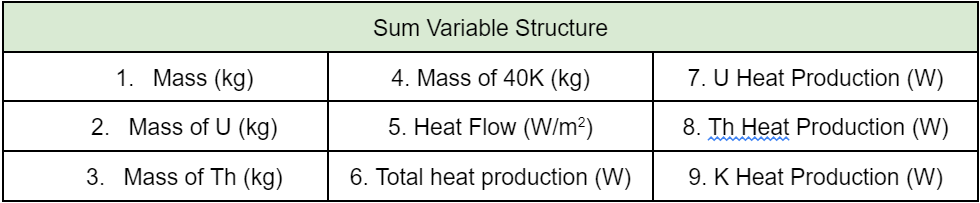

sums = groupMassSums(s1_cc_sums,s2_cc_sums,s3_cc_sums,UC_cc_sums, MC_cc_sums,LC_cc_sums,LM_cc_sums,...
    s1_oc_sums,s2_oc_sums,s3_oc_sums,UC_oc_sums,MC_oc_sums,LC_oc_sums,LM_oc_sums,...
    s1_nf_sums,s2_nf_sums,s3_nf_sums,UC_nf_sums,MC_nf_sums,LC_nf_sums,LM_nf_sums,...
    man_sums_em, man_sums_dm,s1_nf_sums_cc,s2_nf_sums_cc, s3_nf_sums_cc, UC_nf_sums_cc, ...
    MC_nf_sums_cc, LC_nf_sums_cc, LM_nf_sums_cc);

- Congregate "flux" variables and calculate signal in TNU

U238 = 1:length(simple2.energy); %1:19
Th232 = length(simple2.energy)+1:length(simple2.energy)*2; %20:38


flux = groupFluxSums(calcMantle,s1_cc_flux_sums,s2_cc_flux_sums,s3_cc_flux_sums,...
    UC_cc_flux_sums, MC_cc_flux_sums,LC_cc_flux_sums,LM_cc_flux_sums,...
    s1_oc_flux_sums,s2_oc_flux_sums,s3_oc_flux_sums,...
    UC_oc_flux_sums,MC_oc_flux_sums,LC_oc_flux_sums,LM_oc_flux_sums,...
    s1_nf_flux_sums,s2_nf_flux_sums,s3_nf_flux_sums,...
    UC_nf_flux_sums,MC_nf_flux_sums,LC_nf_flux_sums,LM_nf_flux_sums,...
    man_flux_sums_em, man_flux_sums_dm, TNU, U238, Th232,...
    s1_distCount_sums, s2_distCount_sums, s3_distCount_sums,...
    UC_distCount_sums, MC_distCount_sums, LC_distCount_sums, LM_distCount_sums,...
    man_distCount_sums_dm, man_distCount_sums_em, s1_nf_flux_sums_cc, s2_nf_flux_sums_cc,s3_nf_flux_sums_cc,...

    UC_nf_flux_sums_cc, MC_nf_flux_sums_cc, LC_nf_flux_sums_cc, LM_nf_flux_sums_cc);

### Save data (~150 mb)

Save the MASTER information file along with the results of the geoneutrino flux calculations.

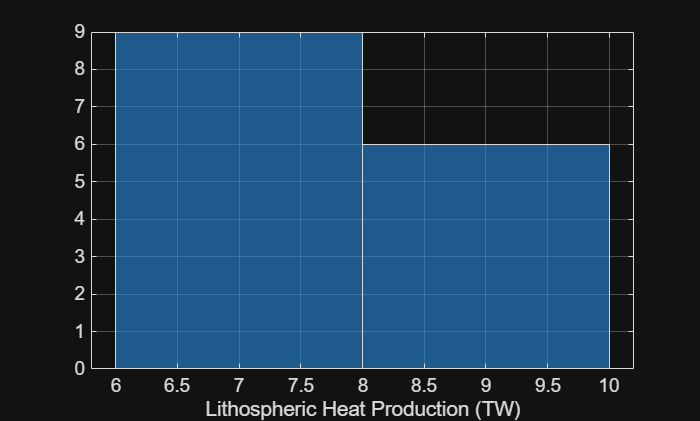

MASTER = orderfields(MASTER); % Re-order the MASTER structure alphabetically

% Record Method used
if strcmp(MASTER.method, 'Huang et al. 2013') == 1
    m = 'H13Meth'; 
else
    m = 'BivarMeth';
end

% Record if calculated flux or not (and what detector)
if size(det,2)>1
    d = sprintf('flux%s',det.Properties.RowNames{1}); 
else
    d = 'noFlux';
end

% Record type of mantle
if strcmp(MASTER.mantle.calc,'true') == 1 
    if strcmp(MASTER.mantle.Style,'Layered') == 1
        e = 'CalcMantleLayered';
    else
        e = 'CalcMantleHomo';
    end
else
    e = 'noCalcMantle';
end


% Make String (add datestr(now) so that you don't overwrite a previous file
% from same day)
str1 = sprintf('%s_Results_%1.1eIter_%s_%s_%s_%s_%s',d,iter,MASTER.model,m,e,datetime('today','format','ddmmmyyyy'),datetime('now','format','HHMM'));
MASTER.save.name = str1; MASTER.save.locate = pwd; 

str.saved = strcat(str1,'.mat');

if calcMantle ==1
    save(str.saved,'MASTER','lith','GeoPhys','s1','s2','s3','UC','MC','LC','LM','mantle','flux','sums','cc','oc','str1','iter','simple2','cor','final_cut')
else

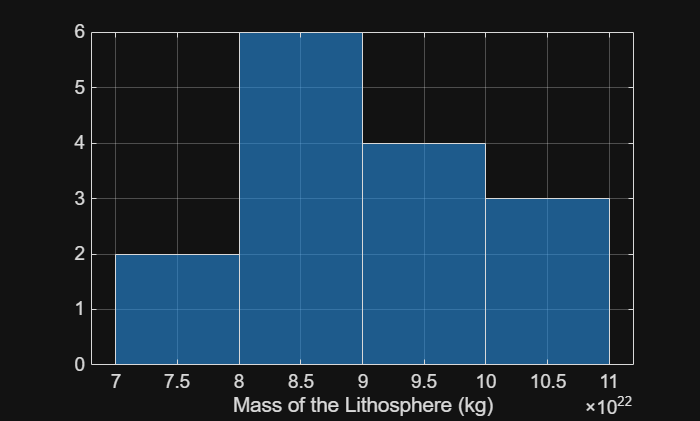

    save(str.saved,'MASTER','lith','GeoPhys','s1','s2','s3','UC','MC','LC','LM','flux','sums','cc','oc','str1','iter','simple2','cor')
end



% clearvars('-except','MASTER','huang','GeoPhys','s1','s2','s3','UC','MC','LC','LM','flux','cc','oc'); 


fprintf('4) Saved data: \n %s \n',str.saved)
fprintf('     %s \n',str.saved)

### Print Run information directly to text file

Print and save a text file with a summary of the information of the code you ran. This is useful for remembering the exact parameters you set for a given run or any errors that occurred that prevented the code from running to completion.

x = gcp; 


str.fid = strcat('RunInfo_',str1,'.txt');
fid = fopen(str.fid,'wt');

fprintf(fid,'Code: "CODE_GeoAbundFlux_master.m" \n'); %print code name 
fprintf(fid,' \n \n \n \n \n') ;% print new lines so that the output is more obvious
fprintf(fid,'------------------------------------------------------ \n');
fprintf(fid,'------------------- Parallel Pool -------------------- \n');
fprintf(fid,'            Connected: %s \n','true');
fprintf(fid,'           NumWorkers: %d \n',x.NumWorkers');
fprintf(fid,'              Cluster: %s \n','local');
fprintf(fid,'          IdleTimeout: %d \n',x.IdleTimeout);
fprintf(fid,'          SpmdEnabled: %s \n','true'); 
    if x.IdleTimeout == 30 %running on cluster
        fprintf(fid,'           Running on: DEEPTHOUGHT2 Cluster \n');
    elseif x.IdleTimeout == 60 %running on desktop (make sure desktop is set to have 60 min!)
        fprintf(fid,'           Running on: DESKTOP \n');
    end

fprintf(fid,' \n \n');
fprintf(fid,'------------------------------------------------------ \n');
fprintf(fid,'------------------- Run information ------------------ \n');
fprintf(fid,'Start date and time:       %s \n',MASTER.start);
fprintf(fid,'Geophysical Model:         %s \n',MASTER.model);
fprintf(fid,'Number of iterations:      %d \n',MASTER.iter);
fprintf(fid,'MC + LC Method:            %s \n',MASTER.method);
fprintf(fid,'Calculate Mantle:          %s \n',MASTER.mantle.calc);
    if strcmp(MASTER.mantle.calc,'true')
    fprintf(fid,'Mantle structure:          %s \n',MASTER.mantle.Style); 
    end
fprintf(fid,'\n ');
fprintf(fid,'Calculate Flux:            %s \n',MASTER.flux.calcFlux);
    if strcmp(MASTER.flux.calcFlux,'true')
fprintf(fid,'Detector (lon lat):        %s (%0.2f %0.2f) \n',det.Properties.RowNames{1},det.Longitude,det.Latitude);
fprintf(fid,'Energy bin size (MeV):     %d \n',MASTER.energy.binsize); 
fprintf(fid,'Near-Field style:          %s \n',MASTER.flux.nearField);
    end
    

fprintf(fid,'\n \n');
fprintf(fid,'------------------------------------------------------ \n');
fprintf(fid,'-------------------- Run Progress -------------------- \n');
fprintf(fid,'1) Lithosphere Monte Carlo... Done (Time Elapsed: %.1f min) \n',runtime.litho);

if calcMantle == 1
fprintf(fid,'2) Mantle Monte Carlo... Done (Time Elapsed: %.1f min) \n',runtime.mantle);
end
fprintf(fid,'3) Re-organizing Data... Done (Time Elapsed: %.1f min) \n',runtime.organize);
fprintf(fid,'4) Saved data: \n %s \n',str.saved);
fprintf(fid,'     %s \n',str.saved) ;
% fprintf(fid,'5) Saved Table: Geo-Physical/Chemical Results');
% fprintf(fid,'     %s \n',str.geo);
% fprintf(fid,'6) Saved Table: Flux Results');
% fprintf(fid,'     %s \n',str.flux);
% fprintf(fid,'7) Saved Figure: Distance vs Flux');
% fprintf(fid,'     %s \n',str.png); 

fprintf(fid,'\n \n ');
fprintf(fid,'------------------------------------------------------ \n');
fprintf(fid,'---------------------- Run End ----------------------- \n');
fprintf(fid,'End date and time:         %s \n',datetime('now','format','mmmm dd, yyyy HH:MM')); 
fprintf(fid,'Total Run time (min):      %0.2f \n',toc(tstart)/60);
fprintf(fid,'\n');
fprintf(fid,'------------------------------------------------------\n');

fclose(fid);
fclose('all'); % Fully releases the file (otherwise Matlab won't for some reason)

% Re-Load text file into "MASTER" variable
    % Initialize variables.
        delimiter = ',';
        startRow = 1;
        endRow = inf;
    % Format string for each line of text:
        formatSpec = '%s%s%[^\n\r]';
    % Open the text file.
        fileID = fopen(str.fid,'r');
    % Read columns of data according to format string.
        textscan(fileID, '%[^\n\r]', startRow(1)-1, 'WhiteSpace', '', 'ReturnOnError', false);
        dataArray = textscan(fileID, formatSpec, endRow(1)-startRow(1)+1, 'Delimiter', delimiter, 'ReturnOnError', false);
        for block=2:length(startRow)
            frewind(fileID);
            textscan(fileID, '%[^\n\r]', startRow(block)-1, 'WhiteSpace', '', 'ReturnOnError', false);
            dataArrayBlock = textscan(fileID, formatSpec, endRow(block)-startRow(block)+1, 'Delimiter', delimiter, 'ReturnOnError', false);
            for col=1:length(dataArray)
                dataArray{col} = [dataArray{col};dataArrayBlock{col}];
            end
        end

    % Close the text file.
        fclose(fileID);
    % Create output variable
        MASTER.runInfo = [dataArray{1:end-1}];

## ***~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-~-***

## Step 7: Visualizing the Results - WORK IN PROGRESS

% Create a plot of different variables     
figure
histogram(lith(:,6)./(1E12))
xlabel('Lithospheric Heat Production (TW)')

figure
histogram(lith(:,1))
xlabel('Mass of the Lithosphere (kg)')

%% 17) ---- Table of Model Geo-parameters (~Huang et al. 2013 Table 3) ---
%{
%The rows of the table are reservoirs.  The columns are average with
%uncertainty for each reservoir. 

%}

m1= 4; % see help "stat"
m2 = 3; 
% note: UC, sed, and LM will always fit using normal dist. maximum
% Liklihood fit because they are always normal (see Section 4)

% Crustal Sediments
weight = s1.mass.mass(cc,1) + s2.mass.mass(cc,1) + s3.mass.mass(cc,1); 
w1 = s1.mass.mass(cc,1)./weight; % weigh each layer by mass so we can combine
w2 = s2.mass.mass(cc,1)./weight; 
w3 = s3.mass.mass(cc,1)./weight; 
sed.thick = s1.thick(cc,:) + s2.thick(cc,:) + s3.thick(cc); 
sed.rho = s1.rho(cc,:).*w1 + s2.rho(cc).*w2 + s3.rho(cc).*w3; 
sed.mass.mass = s1.mass.mass(cc) + s2.mass.mass(cc) + s3.mass.mass(cc); 
sed.mass.U = s1.mass.U(cc) + s2.mass.U(cc) + s3.mass.U(cc); 
sed.mass.Th = s1.mass.Th(cc) + s2.mass.Th(cc) + s3.mass.Th(cc);
sed.mass.K = s1.mass.K(cc) + s2.mass.K(cc) + s3.mass.K(cc);
sed_sums = s1_cc_sums + s2_cc_sums + s3_cc_sums; 

% Oceanic Sediments
weight = s1.mass.mass(oc,1) + s2.mass.mass(oc,1) + s3.mass.mass(oc,1); 
w1 = s1.mass.mass(oc,1)./weight; % weigh each layer by mass so we can combine
w2 = s2.mass.mass(oc,1)./weight; 
w3 = s3.mass.mass(oc,1)./weight; 
sed.oc.thick = s1.thick(oc) + s2.thick(oc,:) + s3.thick(oc,:); 
sed.oc.rho = s1.rho(oc,1).*w1 + s2.rho(oc,1).*w2 + s3.rho(oc,1).*w3; 
sed_oc_sums = s1_oc_sums + s2_oc_sums + s3_oc_sums; 

% Oceanic Crust
weight = UC.mass.mass(oc,1) + MC.mass.mass(oc,1) + LC.mass.mass(oc,1); 
w1 = UC.mass.mass(oc,1)./weight; % weigh each layer by mass so we can combine
w2 = MC.mass.mass(oc,1)./weight; 
w3 = LC.mass.mass(oc,1)./weight; 
ocean.thick = UC.thick(oc) + MC.thick(oc) + LC.thick(oc);
ocean.rho = UC.rho(oc).*w1 + MC.rho(oc).*w2 + LC.rho(oc).*w3; 

ocean_sums = UC_oc_sums + MC_oc_sums + LC_oc_sums; 


% Mantle Stats
if simple2.calcMantleLayered == true
    mantle.dm.thick = 2891-750-GeoPhys.LAB/1000; %km
    mantle.em.thick = 750; 
    mantle.dm.rho = PREM(25:2891-750,3); 
    mantle.em.rho = PREM(2891-750:2891,3);     
else
    mantle.dm.thick = 2891 - GeoPhys.LAB/1000;%km
    mantle.em.thick = 0;
    mantle.dm.rho = PREM(25:2891,3); 
    mantle.em.rho = 0;       
end

% BSE Stats
if calcMantle == 1
bse_sums = s1_cc_sums + s2_cc_sums + s3_cc_sums  + MC_cc_sums...
    + LC_cc_sums + LM_cc_sums + s1_oc_sums + s2_oc_sums + s3_oc_sums + UC_oc_sums...
    + MC_oc_sums + LC_oc_sums + man_sums_dm + man_sums_em; 
else
bse_sums = s1_cc_sums + s2_cc_sums + s3_cc_sums  + MC_cc_sums...
    + LC_cc_sums + LM_cc_sums + s1_oc_sums + s2_oc_sums + s3_oc_sums + UC_oc_sums...
    + MC_oc_sums + LC_oc_sums;
end

sums.bse = bse_sums; 
bse.thick = 2891; %km
bse.rho = bse_sums(:,1)./((4/3*pi*6371000^3)-(4/3*pi*(6371000-2891000)^3));

% Continental Crust Stats
crust_sums = s1_cc_sums + s2_cc_sums + s3_cc_sums + MC_cc_sums...
    + LC_cc_sums; 
sums.bulkCrust = crust_sums; 

x = s1.mass.mass(cc,1) + s2.mass.mass(cc,1) + s3.mass.mass(cc,1) + UC.mass.mass(cc,1)...
    + MC.mass.mass(cc,1) + LC.mass.mass(cc,1); 
crust.rho = s1.rho(cc).*(s1.mass.mass(cc,1)./x) + s2.rho(cc).*(s2.mass.mass(cc,1)./x)...
    + s3.rho(cc).*(s3.mass.mass(cc,1)./x) + UC.rho(cc).*(UC.mass.mass(cc,1)./x)...
    + MC.rho(cc).*(MC.mass.mass(cc,1)./x) + LC.rho(cc).*(LC.mass.mass(cc,1)./x); 

crust.thick = s1.thick(cc) + s2.thick(cc) + s3.thick(cc) + UC.thick(cc)...
    + MC.thick(cc) + LC.thick(cc); 





% Row Names
tab.geo.rows = {'Sed';'UC';'MC';'LC';'Bulk CC';'LM';'Sed';'C';'DM';'EM';'BSE'};
if calcMantle == 1

% - Density (rho; g/cm3) (use 'find' to only get non-zero values as to not mess up stats)
    x = [stat(sed.rho(find(sed.rho)),m2);...
         stat(UC.rho(cc),m2);...
         stat(MC.rho(cc),m2);...
         stat(LC.rho(cc),m2);...
         stat(crust.rho,m2);...
         stat(LM.rho(cc),m2);...
         stat(sed.oc.rho(find(sed.oc.rho)),m2);...
         stat(ocean.rho,m2);...
         stat(mantle.dm.rho,m2);...
         stat(mantle.em.rho,m2);...
         stat(bse.rho,m2)]/1000; %(g/cm3) 
    tab.geo.rho = x; 

% - Thickness (km) (use 'find' to only get non-zero values as to not mess up stats)
    x = [stat(sed.thick(find(sed.thick)),m2);...
        stat(UC.thick(cc),m2);...
        stat(MC.thick(cc),m2);...
        stat(LC.thick(cc),m2);...
        stat(crust.thick,m2);...
        stat(LM.thick(cc),m2);...
        stat(sed.oc.rho,m2);...
        stat(ocean.thick,m2);...
        stat(mantle.dm.thick(cc),m2)*1000;...
        stat(mantle.em.thick,m2)*1000;...
        stat(bse.thick,m2)*1000]/1000; %(km)
    tab.geo.thick = x; 

  
% - Mass (10^21 kg)
    x = [stat(sed_sums(final_cut,1),m2);...
        stat(UC_cc_sums(final_cut,1),m2);...
        stat(MC_cc_sums(final_cut,1),m2);...
        stat(LC_cc_sums(final_cut,1),m2);...
        stat(crust_sums(final_cut,1),m2);...
        stat(LM_cc_sums(final_cut,1),m2);...
        stat(sed_oc_sums(final_cut,1),m2);...
        stat(ocean_sums(final_cut,1),m2);...
        stat(man_sums_dm(final_cut,1),m2);...%only works if mantle is calculated
        stat(man_sums_em(final_cut,1),m2);...%only works if mantle is calculated
        stat(bse_sums(final_cut,1),m2)]/10^21; %(10^21 kg)
    tab.geo.mass.mass = x; 

% - Abundance of U (ppm; ug/g)
    x = [stat(sed_sums(final_cut,2)./sed_sums(final_cut,1),m2);...
        stat(UC_cc_sums(final_cut,2)./MC_cc_sums(final_cut,1),m1);...
        stat(MC_cc_sums(final_cut,2)./MC_cc_sums(final_cut,1),m1);...
        stat(LC_cc_sums(final_cut,2)./LC_cc_sums(final_cut,1),m1);...
        stat(crust_sums(final_cut,2)./crust_sums(final_cut,1),m1);...
        stat(LM_cc_sums(final_cut,2)./LM_cc_sums(final_cut,1),m1);...
        stat(sed_oc_sums(final_cut,2)./sed_oc_sums(final_cut,1),m2);...
        stat(ocean_sums(final_cut,2)./ocean_sums(final_cut,1),m2);...
        stat(man_sums_dm(final_cut,2)./man_sums_dm(final_cut,1),m2);...%only works if mantle is calculated
        stat(man_sums_em(final_cut,2)./man_sums_em(final_cut,1),m2);...%only works if mantle is calculated
        stat(bse_sums(final_cut,2)./bse_sums(final_cut,1),m2)]*10^6; %(ppm)
    tab.geo.abund.U = x;    

    
% - Abundance of Th (ppm; ug/g)
    x = [stat(sed_sums(final_cut,3)./sed_sums(final_cut,1),m2);...
        stat(UC_cc_sums(final_cut,3)./MC_cc_sums(final_cut,1),m1);...
        stat(MC_cc_sums(final_cut,3)./MC_cc_sums(final_cut,1),m1);...
        stat(LC_cc_sums(final_cut,3)./LC_cc_sums(final_cut,1),m1);...
        stat(crust_sums(final_cut,3)./crust_sums(final_cut,1),m1);...
        stat(LM_cc_sums(final_cut,3)./LM_cc_sums(final_cut,1),m1);...
        stat(sed_oc_sums(final_cut,3)./sed_oc_sums(final_cut,1),m2);...
        stat(ocean_sums(final_cut,3)./ocean_sums(final_cut,1),m2);...
        stat(man_sums_dm(final_cut,3)./man_sums_dm(final_cut,1),m2);...%only works if mantle is calculated
        stat(man_sums_em(final_cut,3)./man_sums_em(final_cut,1),m2);...%only works if mantle is calculated
        stat(bse_sums(final_cut,3)./bse_sums(final_cut,1),m2)]*10^6; %(ppm)
    tab.geo.abund.Th = x;   

% - Abundance of K (wt%)
    x = [stat(sed_sums(final_cut,4)./sed_sums(final_cut,1),m2);...
        stat(UC_cc_sums(final_cut,4)./MC_cc_sums(final_cut,1),m1);...
        stat(MC_cc_sums(final_cut,4)./MC_cc_sums(final_cut,1),m1);...
        stat(LC_cc_sums(final_cut,4)./LC_cc_sums(final_cut,1),m1);...
        stat(crust_sums(final_cut,4)./crust_sums(final_cut,1),m1);...
        stat(LM_cc_sums(final_cut,4)./LM_cc_sums(final_cut,1),m1);...
        stat(sed_oc_sums(final_cut,4)./sed_oc_sums(final_cut,1),m2);...
        stat(ocean_sums(final_cut,4)./ocean_sums(final_cut,1),m2);...
        stat(man_sums_dm(final_cut,4)./man_sums_dm(final_cut,1),m2);...%only works if mantle is calculated
        stat(man_sums_em(final_cut,4)./man_sums_em(final_cut,1),m2);...%only works if mantle is calculated
        stat(bse_sums(final_cut,4)./bse_sums(final_cut,1),m2)]*10^6; %(ppm)
    tab.geo.abund.K = x;   
    
% - Mass of U (10^15 kg)
    x = [stat(sed_sums(final_cut,2),m2);...
        stat(UC_cc_sums(final_cut,2),m1);...
        stat(MC_cc_sums(final_cut,2),m1);...
        stat(LC_cc_sums(final_cut,2),m1);...
        stat(crust_sums(final_cut,2),m1);...
        stat(LM_cc_sums(final_cut,2),m1);...
        stat(sed_oc_sums(final_cut,2),m2);...
        stat(ocean_sums(final_cut,2),m2);...
        stat(man_sums_dm(final_cut,2),m2);...%only works if mantle is calculated
        stat(man_sums_em(final_cut,2),m2);...%only works if mantle is calculated
        stat(bse_sums(final_cut,2),m2)]/10^15; %(10^15 kg)
    tab.geo.mass.U = x; 
    
% - Mass of Th (10^15 kg)
    x = [stat(sed_sums(final_cut,3),m2);...
        stat(UC_cc_sums(final_cut,3),m1);...
        stat(MC_cc_sums(final_cut,3),m1);...
        stat(LC_cc_sums(final_cut,3),m1);...
        stat(crust_sums(final_cut,3),m1);...
        stat(LM_cc_sums(final_cut,3),m1);...
        stat(sed_oc_sums(final_cut,3),m2);...
        stat(ocean_sums(final_cut,3),m2);...
        stat(man_sums_dm(final_cut,3),m2);...%only works if mantle is calculated
        stat(man_sums_em(final_cut,3),m2);...%only works if mantle is calculated
        stat(bse_sums(final_cut,3),m2)]/10^15; %(10^15 kg)
    tab.geo.mass.Th = x; 

% - Mass of K (10^19 kg)
    x = [stat(sed_sums(final_cut,4),m2);...
        stat(UC_cc_sums(final_cut,4),m1);...
        stat(MC_cc_sums(final_cut,4),m1);...
        stat(LC_cc_sums(final_cut,4),m1);...
        stat(crust_sums(final_cut,4),m1);...
        stat(LM_cc_sums(final_cut,4),m1);...
        stat(sed_oc_sums(final_cut,4),m2);...
        stat(ocean_sums(final_cut,4),m2);...
        stat(man_sums_dm(final_cut,4),m2);...%only works if mantle is calculated
        stat(man_sums_em(final_cut,4),m2);...%only works if mantle is calculated
        stat(bse_sums(final_cut,4),m2)]/10^19/K.b; %(10^19 kg)
    tab.geo.mass.K = x; 

% - Heat production (TW; 10^12 W)
      x = [stat(sed_sums(final_cut,6),m2);...
          stat(UC_cc_sums(final_cut,6),m1);...
        stat(MC_cc_sums(final_cut,6),m1);...
        stat(LC_cc_sums(final_cut,6),m1);...
        stat(crust_sums(final_cut,6),m1);...
        stat(LM_cc_sums(final_cut,6),m1);...
        stat(sed_oc_sums(final_cut,6),m2);...
        stat(ocean_sums(final_cut,6),m2);...
        stat(man_sums_dm(final_cut,6),m2);...%only works if mantle is calculated
        stat(man_sums_em(final_cut,6),m2);...%only works if mantle is calculated
        stat(bse_sums(final_cut,6),m2)]/10^12; %(10^12 W (TW))
    tab.geo.hp = x;

  
    

% Horizontal concatenate and print 

    tab.geo.table = horzcat(tab.geo.rho, tab.geo.thick, tab.geo.mass.mass, tab.geo.abund.U,...
        tab.geo.abund.Th, tab.geo.abund.K, tab.geo.mass.U, tab.geo.mass.Th,...
        tab.geo.mass.K, tab.geo.hp); %only works if mantle is calculated

  else
          x = [stat(sed.rho(find(sed.rho)),m2);...
         stat(UC.rho(cc),m2);...
         stat(MC.rho(cc),m2);...
         stat(LC.rho(cc),m2);...
         stat(crust.rho,m2);...
         stat(LM.rho(cc),m2);...
         stat(sed.oc.rho(find(sed.oc.rho)),m2);...
         stat(ocean.rho,m2);...
         stat(bse.rho,m2)]/1000; %(g/cm3) 
    tab.geo.rho = x; 

% - Thickness (km) (use 'find' to only get non-zero values as to not mess up stats)
    x = [stat(sed.thick(find(sed.thick)),m2);...
        stat(UC.thick(cc),m2);...
        stat(MC.thick(cc),m2);...
        stat(LC.thick(cc),m2);...
        stat(crust.thick,m2);...
        stat(LM.thick(cc),m2);...
        stat(sed.oc.rho,m2);...
        stat(ocean.thick,m2);...
        stat(bse.thick,m2)*1000]/1000; %(km)
    tab.geo.thick = x; 

        % - Mass (10^21 kg)
    x = [stat(sed_sums(:,1),m2);...
        stat(UC_cc_sums(:,1),m2);...
        stat(MC_cc_sums(:,1),m2);...
        stat(LC_cc_sums(:,1),m2);...
        stat(crust_sums(:,1),m2);...
        stat(LM_cc_sums(:,1),m2);...
        stat(sed_oc_sums(:,1),m2);...
        stat(ocean_sums(:,1),m2);...
        stat(bse_sums(:,1),m2)]/10^21; %(10^21 kg)
    tab.geo.mass.mass = x; 

% - Abundance of U (ppm; ug/g)
    x = [stat(sed_sums(:,2)./sed_sums(:,1),m2);...
        stat(UC_cc_sums(:,2)./UC_cc_sums(:,1),m1);...
        stat(MC_cc_sums(:,2)./MC_cc_sums(:,1),m1);...
        stat(LC_cc_sums(:,2)./LC_cc_sums(:,1),m1);...
        stat(crust_sums(:,2)./crust_sums(:,1),m1);...
        stat(LM_cc_sums(:,2)./LM_cc_sums(:,1),m1);...
        stat(sed_oc_sums(:,2)./sed_oc_sums(:,1),m2);...
        stat(ocean_sums(:,2)./ocean_sums(:,1),m2);...
        stat(bse_sums(:,2)./bse_sums(:,1),m2)]*10^6; %(ppm)
    tab.geo.abund.U = x;    

    
% - Abundance of Th (ppm; ug/g)
    x = [stat(sed_sums(:,3)./sed_sums(:,1),m2);...
        stat(UC_cc_sums(:,3)./UC_cc_sums(:,1),m1);...
        stat(MC_cc_sums(:,3)./MC_cc_sums(:,1),m1);...
        stat(LC_cc_sums(:,3)./LC_cc_sums(:,1),m1);...
        stat(crust_sums(:,3)./crust_sums(:,1),m1);...
        stat(LM_cc_sums(:,3)./LM_cc_sums(:,1),m1);...
        stat(sed_oc_sums(:,3)./sed_oc_sums(:,1),m2);...
        stat(ocean_sums(:,3)./ocean_sums(:,1),m2);...
        stat(bse_sums(:,3)./bse_sums(:,1),m2)]*10^6; %(ppm)
    tab.geo.abund.Th = x;   

% - Abundance of K (wt%)
    x = [stat(sed_sums(:,4)./sed_sums(:,1),m2);...
        stat(UC_cc_sums(:,4)./UC_cc_sums(:,1),m1);...
        stat(MC_cc_sums(:,4)./MC_cc_sums(:,1),m1);...
        stat(LC_cc_sums(:,4)./LC_cc_sums(:,1),m1);...
        stat(crust_sums(:,4)./crust_sums(:,1),m1);...
        stat(LM_cc_sums(:,4)./LM_cc_sums(:,1),m1);...
        stat(sed_oc_sums(:,4)./sed_oc_sums(:,1),m2);...
        stat(ocean_sums(:,4)./ocean_sums(:,1),m2);...
        stat(bse_sums(:,4)./bse_sums(:,1),m2)]*10^6; %(ppm)
    tab.geo.abund.K = x;   
    
% - Mass of U (10^15 kg)
    x = [stat(sed_sums(:,2),m2);...
        stat(UC_cc_sums(:,2),m1);...
        stat(MC_cc_sums(:,2),m1);...
        stat(LC_cc_sums(:,2),m1);...
        stat(crust_sums(:,2),m1);...
        stat(LM_cc_sums(:,2),m1);...
        stat(sed_oc_sums(:,2),m2);...
        stat(ocean_sums(:,2),m2);...
        stat(bse_sums(:,2),m2)]/10^15; %(10^15 kg)
    tab.geo.mass.U = x; 
    
% - Mass of Th (10^15 kg)
    x = [stat(sed_sums(:,3),m2);...
        stat(UC_cc_sums(:,3),m1);...
        stat(MC_cc_sums(:,3),m1);...
        stat(LC_cc_sums(:,3),m1);...
        stat(crust_sums(:,3),m1);...
        stat(LM_cc_sums(:,3),m1);...
        stat(sed_oc_sums(:,3),m2);...
        stat(ocean_sums(:,3),m2);...
        stat(bse_sums(:,3),m2)]/10^15; %(10^15 kg)
    tab.geo.mass.Th = x; 

% - Mass of K (10^19 kg)
    x = [stat(sed_sums(:,4),m2);...
        stat(UC_cc_sums(:,4),m1);...
        stat(MC_cc_sums(:,4),m1);...
        stat(LC_cc_sums(:,4),m1);...
        stat(crust_sums(:,4),m1);...
        stat(LM_cc_sums(:,4),m1);...
        stat(sed_oc_sums(:,4),m2);...
        stat(ocean_sums(:,4),m2);...
        stat(bse_sums(:,4),m2)]/10^19/K.b; %(10^19 kg)
    tab.geo.mass.K = x; 

% - Heat production (TW; 10^12 W)
      x = [stat(sed_sums(:,6),m2);...
        stat(UC_cc_sums(:,6),m1);...
        stat(MC_cc_sums(:,6),m1);...
        stat(LC_cc_sums(:,6),m1);...
        stat(crust_sums(:,6),m1);...
        stat(LM_cc_sums(:,6),m1);...
        stat(sed_oc_sums(:,6),m2);...
        stat(ocean_sums(:,6),m2);...
        stat(bse_sums(:,6),m2)]/10^12; %(10^12 W (TW))
    tab.geo.hp = x;

  
    

% Horizontal concatenate and print 

    tab.geo.table = horzcat(tab.geo.rho, tab.geo.thick, tab.geo.mass.mass, tab.geo.abund.U,...
        tab.geo.abund.Th, tab.geo.abund.K, tab.geo.mass.U, tab.geo.mass.Th,...
        tab.geo.mass.K, tab.geo.hp);
    end

